## **HCP Main Sample - External Validation 'Expanded NMA Model' in HCP Lockbox Sample **

Conduction of the external cross-validation of the 'Expanded NMA Model' that is built using 14 input predictor variables. The predictor variables are derived from individual's coupling values and extracted by using group-based positive and negative NMA masks. The script contains three parts: **Part 1 **partitions the sample into five different folds (considering family relations and intelligence distribution) and creates a positive and negative NMAs for each training fold (4/5 partition) and test fold (in this case the lockbox sample). **Part 2 **uses the NMAs created in part 1 to build multiple linear regression models that are then tested for their ability to predict general intelligence in the test samples (lockbox sample in this case). **Part 3 **assesses the significance of the prediction model with a permutation test. 

Before running this script:

- run all scripts in HCP Data Prep 

**Part 1**

Partitioning the sample into 5 different folds and creating the positive and negative NMAs for each training fold and test fold (in this case the lockbox sample) based on the correllation with general intelligence scores. 

**1. Prepare data for the main sample (HCP 532) **

**1. 1. Prepare the coupling data for the emotion task - main sample **

1.1.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_emotion_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_emotion{i,j} = x(j,:);
    end
end

1.1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_emotion,2);
All_Nodes_complete_HCP_emotion = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_emotion{j} = vertcat(Node_all_baseline_HCP_emotion{:,j});
end 

1.1.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_emotion{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_emotion_4_measures{1,i} = four_measures_per_node;
end

**1.2. Prepare the coupling data for the gambling task - main sample **

1.2.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_gambling_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_gambling{i,j} = x(j,:);
    end
end

1.2.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_gambling,2);
All_Nodes_complete_HCP_gambling = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_gambling{j} = vertcat(Node_all_baseline_HCP_gambling{:,j});
end 

1.2.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_gambling{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_gambling_4_measures{1,i} = four_measures_per_node;
end

**1.3. Prepare the coupling data for the language task - main sample**

1.3.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_language_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_language{i,j} = x(j,:);
    end
end

1.3.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_language,2);
All_Nodes_complete_HCP_language = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_language{j} = vertcat(Node_all_baseline_HCP_language{:,j});
end 

1.3.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_language{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_language_4_measures{1,i} = four_measures_per_node;
end

**1.4. Prepare the coupling data for the motor task - main sample**

1.4.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_motor_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_motor{i,j} = x(j,:);
    end
end

1.4.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_motor,2);
All_Nodes_complete_HCP_motor = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_motor{j} = vertcat(Node_all_baseline_HCP_motor{:,j});
end 

1.4.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_motor{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_motor_4_measures{1,i} = four_measures_per_node;
end

**1.5. Prepare the coupling data for the relational processing task - main sample **

1.5.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_relational_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_relational{i,j} = x(j,:);
    end
end

1.5.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_relational,2);
All_Nodes_complete_HCP_relational = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_relational{j} = vertcat(Node_all_baseline_HCP_relational{:,j});
end 

1.5.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_relational{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_relational_4_measures{1,i} = four_measures_per_node;
end

**1.6. Prepare the coupling data for the social cognition task - main sample **

1.6.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_social_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_social{i,j} = x(j,:);
    end
end

1.6.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_social,2);
All_Nodes_complete_HCP_social = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_social{j} = vertcat(Node_all_baseline_HCP_social{:,j});
end 

1.6.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_social{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_social_4_measures{1,i} = four_measures_per_node;
end

**1.7. Prepare the coupling data for the working memory task - main sample **

1.7.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_wm_532{i,1};
    for j = 1:358
    Node_all_baseline_HCP_wm{i,j} = x(j,:);
    end
end

1.7.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_HCP_wm,2);
All_Nodes_complete_HCP_wm = cell(1,n);
for j = 1:n
    All_Nodes_complete_HCP_wm{j} = vertcat(Node_all_baseline_HCP_wm{:,j});
end 

1.7.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3), & Search Information (4)

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_HCP_wm{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_HCP_wm_4_measures{1,i} = four_measures_per_node;
end

**2. Prepare data for the lockbox sample (HCP 232) **

**2.1. Prepare the coupling data for the emotion task- lockbox sample **

2.1.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:232
    x = final_r_all_HCP_emotion_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_emotion_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (232*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_emotion_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_emotion_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_emotion_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_emotion_lockbox_weighted_only{:,j});
end 

2.1.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_emotion_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_emotion_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**2.2. Prepare the coupling data for the gambling task - lockbox sample**

2.2.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:232
    x = final_r_all_HCP_gambling_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_gambling_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.2.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (232*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_gambling_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_gambling_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_gambling_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_gambling_lockbox_weighted_only{:,j});
end 

2.2.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_gambling_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_gambling_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**2.3. Prepare the coupling data for the language task - lockbox sample **

2.3.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:232
    x = final_r_all_HCP_language_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_language_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.3.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (232*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_language_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_language_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_language_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_language_lockbox_weighted_only{:,j});
end 

2.3.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_language_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_language_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**2.4. Prepare the coupling data for the motor task - lockbox sample**

2.4.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:232
    x = final_r_all_HCP_motor_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_motor_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.4.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (232*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_motor_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_motor_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_motor_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_motor_lockbox_weighted_only{:,j});
end 

2.4.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_motor_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_motor_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**2.5. Prepare the coupling data for the relational processing task - lockbox sample **

2.5.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:232
    x = final_r_all_HCP_relational_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_relational_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.5.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (232*8)

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_relational_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_relat_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_relat_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_relational_lockbox_weighted_only{:,j});
end 

2.5.3.  Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_relat_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_relational_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**2.6. Prepare the coupling data for the social cognition task - lockbox sample **

2.6.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:232
    x = final_r_all_HCP_social_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_social_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.6.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (532*8)

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_social_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_social_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_social_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_social_lockbox_weighted_only{:,j});
end 

2.6.3. Only keep 4 measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_social_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_social_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**2.7. Prepare the coupling data for the working memory task - lockbox sample **

2.7.1. Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:232
    x = final_r_all_HCP_wm_232{i,1};
    for j = 1:358
    Node_all_baseline_HCP_wm_lockbox_weighted_only{i,j} = x(j,:);
    end
end

2.7.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (232*8)

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 232*8 matrix for each node)

n = size(Node_all_baseline_HCP_wm_lockbox_weighted_only,2);
All_Nodes_complete_baseline_HCP_wm_lockbox_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_HCP_wm_lockbox_weighted_only{j} = vertcat(Node_all_baseline_HCP_wm_lockbox_weighted_only{:,j});
end 

2.7.3. Only keep 4 Measures: Path Length (1), Communicability (2), Cosine Distance (3) & Search Information (4) 

for i = 1:358
    eight_measures_per_node =  All_Nodes_complete_baseline_HCP_wm_lockbox_weighted_only{1,i};
    four_measures_per_node_lockbox = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_HCP_wm_lockbox_4_measures{1,i} = four_measures_per_node_lockbox;
end

**3.  Split into 5 folds **

3.1. Create a Loop to do the partition 100 times 

for cross_validation_round = 1:100
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

3.2. Create cross-validation partition based on family IQ

This part of the script creates a partition for the internal cross validation of the linear regression model that is stratified based on Family IQ. That way, we respect the family structures in the HCP and create a distribution of subjects in the test and training samples that is not biased towards general intelligence scores. 

3.2.1.  Assign the variables

HCP_family_ID = HCP_behavioral_532.Family_ID;
HCP_subject_names = HCP_behavioral_532.("Subject Name");
HCP_intelligence_score = HCP_behavioral_532.NEOFAC_E;

3.2.2. Create a table containing all the information that I need 

[number_of_families,~,family_group_number] = unique(HCP_behavioral_532.Family_ID); 
% there are 268 families in the main main sample (unique output 1)

for i = 1:268 % because there is 268 families in the sample (unique output 1) 
    
    indices_for_same_family = find(family_group_number == i);
    subject_ID_same_fam = HCP_subject_names(indices_for_same_family);
    family_ID_original = HCP_family_ID(indices_for_same_family);
    intelligence_score_same_fam = HCP_intelligence_score(indices_for_same_family);
    
    family_info_HCP{i,1} = i;
    family_info_HCP{i,2} = family_ID_original;
    family_info_HCP{i,3} = indices_for_same_family;
    family_info_HCP{i,4} = subject_ID_same_fam;
    family_info_HCP{i,5} = intelligence_score_same_fam;
    
end

3.2.3. Create a family intelligence score

for i = 1:268
    family_intelligence_separate = family_info_HCP{i,5};
    family_intelligence_average = mean(family_intelligence_separate);
    family_info_HCP{i,6} = family_intelligence_average;
end

3.2.4. Convert cell to table

family_info_HCP_table = cell2table(family_info_HCP);
family_info_HCP_table.Properties.VariableNames = {'Group Number','Original_Family_ID', 'Indices_for_same_Family', 'Subject_ID_same_fam', 'intelligence_score_separate_same_fam', 'Mean_intelligence_score_same_fam'};

3.2.5. Create a CV partition based on family IQ (for the families) 

Family_intelligence = family_info_HCP_table.Mean_intelligence_score_same_fam;


Intelligence_for_cv_partition_1 = rescale(Family_intelligence,1,30);
Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

3.2.6. Create output: indices for the families

% Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));

% Train 2 & Test 2 
index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

% Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

% Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

% Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));


3.2.7. Reassign the individual subjects back into the groups from the partition 

% Train 1 & Test 1 

test_1 = family_info_HCP_table.Indices_for_same_Family(index_test_1);
index_test_1_fam = cat(1,test_1{:,1});
index_test_1_fam = sort(index_test_1_fam,"ascend");

train_1 = family_info_HCP_table.Indices_for_same_Family(index_train_1);
index_train_1_fam = cat(1,train_1{:,1});
index_train_1_fam = sort(index_train_1_fam,"ascend");

% Train 2 & Test 2 

test_2 = family_info_HCP_table.Indices_for_same_Family(index_test_2);
index_test_2_fam = cat(1,test_2{:,1});
index_test_2_fam = sort(index_test_2_fam,"ascend");

train_2 = family_info_HCP_table.Indices_for_same_Family(index_train_2);
index_train_2_fam = cat(1,train_2{:,1});
index_train_2_fam = sort(index_train_2_fam,"ascend");


% Train 3 & Test 3 

test_3 = family_info_HCP_table.Indices_for_same_Family(index_test_3);
index_test_3_fam = cat(1,test_3{:,1});
index_test_3_fam = sort(index_test_3_fam,"ascend");

train_3 = family_info_HCP_table.Indices_for_same_Family(index_train_3);
index_train_3_fam = cat(1,train_3{:,1});
index_train_3_fam = sort(index_train_3_fam,"ascend");


% Train 4 & Test 4 

test_4 = family_info_HCP_table.Indices_for_same_Family(index_test_4);
index_test_4_fam = cat(1,test_4{:,1});
index_test_4_fam = sort(index_test_4_fam,"ascend");

train_4 = family_info_HCP_table.Indices_for_same_Family(index_train_4);
index_train_4_fam = cat(1,train_4{:,1});
index_train_4_fam = sort(index_train_4_fam,"ascend");


% Train 5 & Test 5 

test_5 = family_info_HCP_table.Indices_for_same_Family(index_test_5);
index_test_5_fam = cat(1,test_5{:,1});
index_test_5_fam = sort(index_test_5_fam,"ascend");

train_5 = family_info_HCP_table.Indices_for_same_Family(index_train_5);
index_train_5_fam = cat(1,train_5{:,1});
index_train_5_fam = sort(index_train_5_fam,"ascend");

% done with creating the training/test partition

3.3.  Divide data in test and training samples 

3.3.1.1.  **Emotion Processing**: Divide the coupling data into 5 training samples

for i = 1:358
   all_data_node_emotion = All_Nodes_complete_HCP_emotion_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node_emotion(index_train_1_fam,:);
   Node_training_sample_2 = all_data_node_emotion(index_train_2_fam,:);  
   Node_training_sample_3 = all_data_node_emotion(index_train_3_fam,:);
   Node_training_sample_4 = all_data_node_emotion(index_train_4_fam,:);
   Node_training_sample_5 = all_data_node_emotion(index_train_5_fam,:);
   
   
   All_Nodes_complete_cross_validation_HCP_emotion{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_emotion{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_emotion{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_emotion{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_emotion{5,i} = Node_training_sample_5;
   
end

3.3.1.2.  **Gambling Task**: Divide the coupling data into 5 training samples

for i = 1:358
   all_data_node_gambling = All_Nodes_complete_HCP_gambling_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node_gambling(index_train_1_fam,:);
   Node_training_sample_2 = all_data_node_gambling(index_train_2_fam,:);
   Node_training_sample_3 = all_data_node_gambling(index_train_3_fam,:);
   Node_training_sample_4 = all_data_node_gambling(index_train_4_fam,:);
   Node_training_sample_5 = all_data_node_gambling(index_train_5_fam,:);
   
   
   All_Nodes_complete_cross_validation_HCP_gambling{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_gambling{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_gambling{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_gambling{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_gambling{5,i} = Node_training_sample_5;
   
end

3.3.1.3.  **Language Task**: Divide the coupling data into 5 training samples

for i = 1:358
   all_data_node_language = All_Nodes_complete_HCP_language_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node_language(index_train_1_fam,:);
   Node_training_sample_2 = all_data_node_language(index_train_2_fam,:);
   Node_training_sample_3 = all_data_node_language(index_train_3_fam,:);
   Node_training_sample_4 = all_data_node_language(index_train_4_fam,:);
   Node_training_sample_5 = all_data_node_language(index_train_5_fam,:);
   
   
   All_Nodes_complete_cross_validation_HCP_language{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_language{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_language{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_language{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_language{5,i} = Node_training_sample_5;
   
end

3.3.1.4.  **Motor Task**: Divide the coupling data into 5 training samples

for i = 1:358
   all_data_node_motor = All_Nodes_complete_HCP_motor_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node_motor(index_train_1_fam,:);
   Node_training_sample_2 = all_data_node_motor(index_train_2_fam,:);
   Node_training_sample_3 = all_data_node_motor(index_train_3_fam,:);
   Node_training_sample_4 = all_data_node_motor(index_train_4_fam,:);
   Node_training_sample_5 = all_data_node_motor(index_train_5_fam,:);
   
   
   All_Nodes_complete_cross_validation_HCP_motor{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_motor{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_motor{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_motor{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_motor{5,i} = Node_training_sample_5;
   
end

3.3.1.5. **Relational Processing Task**: Divide the coupling data into 5 training samples

for i = 1:358
   all_data_node_relational= All_Nodes_complete_HCP_relational_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node_relational(index_train_1_fam,:);
   Node_training_sample_2 = all_data_node_relational(index_train_2_fam,:);
   Node_training_sample_3 = all_data_node_relational(index_train_3_fam,:);
   Node_training_sample_4 = all_data_node_relational(index_train_4_fam,:);
   Node_training_sample_5 = all_data_node_relational(index_train_5_fam,:);
   
   
   All_Nodes_complete_cross_validation_HCP_relational{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_relational{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_relational{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_relational{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_relational{5,i} = Node_training_sample_5;
   
end

3.3.1.6.  **Social Cognition Task**: Divide the coupling data into 5 training samples

for i = 1:358
   all_data_node_social= All_Nodes_complete_HCP_social_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node_social(index_train_1_fam,:);
   Node_training_sample_2 = all_data_node_social(index_train_2_fam,:);
   Node_training_sample_3 = all_data_node_social(index_train_3_fam,:);
   Node_training_sample_4 = all_data_node_social(index_train_4_fam,:);
   Node_training_sample_5 = all_data_node_social(index_train_5_fam,:);
   
   
   All_Nodes_complete_cross_validation_HCP_social{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_social{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_social{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_social{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_social{5,i} = Node_training_sample_5;

end

3.3.1.7.  **Working Memory Task**: Divide the coupling data into 5 training samples

for i = 1:358
   all_data_node_wm = All_Nodes_complete_HCP_wm_4_measures{1,i};
   
   Node_training_sample_1 = all_data_node_wm(index_train_1_fam,:);
   Node_training_sample_2 = all_data_node_wm(index_train_2_fam,:);
   Node_training_sample_3 = all_data_node_wm(index_train_3_fam,:);
   Node_training_sample_4 = all_data_node_wm(index_train_4_fam,:);
   Node_training_sample_5 = all_data_node_wm(index_train_5_fam,:);
   
   
   All_Nodes_complete_cross_validation_HCP_wm{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_wm{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_wm{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_wm{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_wm{5,i} = Node_training_sample_5;
   
end

3.3.2. Divide intelligence into 5 Training Samples 

Intelligence = HCP_behavioral_532.gscore;
Intelligence_lockbox = HCP_behavioral_232.gscore;

Intelligence_train_1 = Intelligence(index_train_1_fam,:);
Intelligence_train_2 = Intelligence(index_train_2_fam,:);
Intelligence_train_3 = Intelligence(index_train_3_fam,:);
Intelligence_train_4 = Intelligence(index_train_4_fam,:);
Intelligence_train_5 = Intelligence(index_train_5_fam,:);

Intelligence_training_samples{1,:} = Intelligence_train_1;
Intelligence_training_samples{2,:} = Intelligence_train_2;
Intelligence_training_samples{3,:} = Intelligence_train_3;
Intelligence_training_samples{4,:} = Intelligence_train_4;
Intelligence_training_samples{5,:} = Intelligence_train_5;

3.3.3.  Divide Confounding variables into 5 training samples 

Age = HCP_behavioral_532.Age_in_Yrs;
Age_lockbox = HCP_behavioral_232.Age_in_Yrs;

Age_train_1 = Age(index_train_1_fam,:);
Age_train_2 = Age(index_train_2_fam,:);
Age_train_3 = Age(index_train_3_fam,:);
Age_train_4 = Age(index_train_4_fam,:);
Age_train_5 = Age(index_train_5_fam,:);


Age_training_samples{1,:} = Age_train_1;
Age_training_samples{2,:} = Age_train_2;
Age_training_samples{3,:} = Age_train_3;
Age_training_samples{4,:} = Age_train_4;
Age_training_samples{5,:} = Age_train_5;

Gender = HCP_behavioral_532.gender_num;
Gender_lockbox = HCP_behavioral_232.gender_num;

Gender_train_1 = Gender(index_train_1_fam,:);
Gender_train_2 = Gender(index_train_2_fam,:);
Gender_train_3 = Gender(index_train_3_fam,:);
Gender_train_4 = Gender(index_train_4_fam,:);
Gender_train_5 = Gender(index_train_5_fam,:);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

meanFDJenk_emotion = HCP_behavioral_532.mean_mean_RMS_emotion;
meanFDJenk_emotion_lockbox = HCP_behavioral_232.mean_mean_RMS_emotion;

meanFDJenk_emotion_train_1 = meanFDJenk_emotion(index_train_1_fam,:);
meanFDJenk_emotion_train_2 = meanFDJenk_emotion(index_train_2_fam,:);
meanFDJenk_emotion_train_3 = meanFDJenk_emotion(index_train_3_fam,:);
meanFDJenk_emotion_train_4 = meanFDJenk_emotion(index_train_4_fam,:);
meanFDJenk_emotion_train_5 = meanFDJenk_emotion(index_train_5_fam,:);

meanFDJenk_emotion_training_samples{1,:} = meanFDJenk_emotion_train_1;
meanFDJenk_emotion_training_samples{2,:} = meanFDJenk_emotion_train_2;
meanFDJenk_emotion_training_samples{3,:} = meanFDJenk_emotion_train_3;
meanFDJenk_emotion_training_samples{4,:} = meanFDJenk_emotion_train_4;
meanFDJenk_emotion_training_samples{5,:} = meanFDJenk_emotion_train_5;

meanFDJenk_gambling = HCP_behavioral_532.mean_mean_RMS_gambling;
meanFDJenk_gambling_lockbox = HCP_behavioral_232.mean_mean_RMS_gambling;

meanFDJenk_gambling_train_1 = meanFDJenk_gambling(index_train_1_fam,:);
meanFDJenk_gambling_train_2 = meanFDJenk_gambling(index_train_2_fam,:);
meanFDJenk_gambling_train_3 = meanFDJenk_gambling(index_train_3_fam,:);
meanFDJenk_gambling_train_4 = meanFDJenk_gambling(index_train_4_fam,:);
meanFDJenk_gambling_train_5 = meanFDJenk_gambling(index_train_5_fam,:);


meanFDJenk_gambling_training_samples{1,:} = meanFDJenk_gambling_train_1;
meanFDJenk_gambling_training_samples{2,:} = meanFDJenk_gambling_train_2;
meanFDJenk_gambling_training_samples{3,:} = meanFDJenk_gambling_train_3;
meanFDJenk_gambling_training_samples{4,:} = meanFDJenk_gambling_train_4;
meanFDJenk_gambling_training_samples{5,:} = meanFDJenk_gambling_train_5;

meanFDJenk_language = HCP_behavioral_532.mean_mean_RMS_language;
meanFDJenk_language_lockbox = HCP_behavioral_232.mean_mean_RMS_language;

meanFDJenk_language_train_1 = meanFDJenk_language(index_train_1_fam,:);
meanFDJenk_language_train_2 = meanFDJenk_language(index_train_2_fam,:);
meanFDJenk_language_train_3 = meanFDJenk_language(index_train_3_fam,:);
meanFDJenk_language_train_4 = meanFDJenk_language(index_train_4_fam,:);
meanFDJenk_language_train_5 = meanFDJenk_language(index_train_5_fam,:);

meanFDJenk_language_training_samples{1,:} = meanFDJenk_language_train_1;
meanFDJenk_language_training_samples{2,:} = meanFDJenk_language_train_2;
meanFDJenk_language_training_samples{3,:} = meanFDJenk_language_train_3;
meanFDJenk_language_training_samples{4,:} = meanFDJenk_language_train_4;
meanFDJenk_language_training_samples{5,:} = meanFDJenk_language_train_5;

meanFDJenk_motor = HCP_behavioral_532.mean_mean_RMS_motor;
meanFDJenk_motor_lockbox = HCP_behavioral_232.mean_mean_RMS_motor;

meanFDJenk_motor_train_1 = meanFDJenk_motor(index_train_1_fam,:);
meanFDJenk_motor_train_2 = meanFDJenk_motor(index_train_2_fam,:);
meanFDJenk_motor_train_3 = meanFDJenk_motor(index_train_3_fam,:);
meanFDJenk_motor_train_4 = meanFDJenk_motor(index_train_4_fam,:);
meanFDJenk_motor_train_5 = meanFDJenk_motor(index_train_5_fam,:);


meanFDJenk_motor_training_samples{1,:} = meanFDJenk_motor_train_1;
meanFDJenk_motor_training_samples{2,:} = meanFDJenk_motor_train_2;
meanFDJenk_motor_training_samples{3,:} = meanFDJenk_motor_train_3;
meanFDJenk_motor_training_samples{4,:} = meanFDJenk_motor_train_4;
meanFDJenk_motor_training_samples{5,:} = meanFDJenk_motor_train_5;

meanFDJenk_relational = HCP_behavioral_532.mean_mean_RMS_relational;
meanFDJenk_relational_lockbox = HCP_behavioral_232.mean_mean_RMS_relational;

meanFDJenk_relational_train_1 = meanFDJenk_relational(index_train_1_fam,:);
meanFDJenk_relational_train_2 = meanFDJenk_relational(index_train_2_fam,:);
meanFDJenk_relational_train_3 = meanFDJenk_relational(index_train_3_fam,:);
meanFDJenk_relational_train_4 = meanFDJenk_relational(index_train_4_fam,:);
meanFDJenk_relational_train_5 = meanFDJenk_relational(index_train_5_fam,:);


meanFDJenk_relational_training_samples{1,:} = meanFDJenk_relational_train_1;
meanFDJenk_relational_training_samples{2,:} = meanFDJenk_relational_train_2;
meanFDJenk_relational_training_samples{3,:} = meanFDJenk_relational_train_3;
meanFDJenk_relational_training_samples{4,:} = meanFDJenk_relational_train_4;
meanFDJenk_relational_training_samples{5,:} = meanFDJenk_relational_train_5;

meanFDJenk_social = HCP_behavioral_532.mean_mean_RMS_social;
meanFDJenk_social_lockbox = HCP_behavioral_232.mean_mean_RMS_social;

meanFDJenk_social_train_1 = meanFDJenk_social(index_train_1_fam,:);
meanFDJenk_social_train_2 = meanFDJenk_social(index_train_2_fam,:);
meanFDJenk_social_train_3 = meanFDJenk_social(index_train_3_fam,:);
meanFDJenk_social_train_4 = meanFDJenk_social(index_train_4_fam,:);
meanFDJenk_social_train_5 = meanFDJenk_social(index_train_5_fam,:);

meanFDJenk_social_training_samples{1,:} = meanFDJenk_social_train_1;
meanFDJenk_social_training_samples{2,:} = meanFDJenk_social_train_2;
meanFDJenk_social_training_samples{3,:} = meanFDJenk_social_train_3;
meanFDJenk_social_training_samples{4,:} = meanFDJenk_social_train_4;
meanFDJenk_social_training_samples{5,:} = meanFDJenk_social_train_5;

meanFDJenk_wm = HCP_behavioral_532.mean_mean_RMS_wm;
meanFDJenk_wm_lockbox = HCP_behavioral_232.mean_mean_RMS_wm;

meanFDJenk_wm_train_1 = meanFDJenk_wm(index_train_1_fam,:);
meanFDJenk_wm_train_2 = meanFDJenk_wm(index_train_2_fam,:);
meanFDJenk_wm_train_3 = meanFDJenk_wm(index_train_3_fam,:);
meanFDJenk_wm_train_4 = meanFDJenk_wm(index_train_4_fam,:);
meanFDJenk_wm_train_5 = meanFDJenk_wm(index_train_5_fam,:);

meanFDJenk_wm_training_samples{1,:} = meanFDJenk_wm_train_1;
meanFDJenk_wm_training_samples{2,:} = meanFDJenk_wm_train_2;
meanFDJenk_wm_training_samples{3,:} = meanFDJenk_wm_train_3;
meanFDJenk_wm_training_samples{4,:} = meanFDJenk_wm_train_4;
meanFDJenk_wm_training_samples{5,:} = meanFDJenk_wm_train_5;

LQ = HCP_behavioral_532.Handedness;
LQ_lockbox = HCP_behavioral_232.Handedness;

LQ_train_1 = LQ(index_train_1_fam,:);
LQ_train_2 = LQ(index_train_2_fam,:);
LQ_train_3 = LQ(index_train_3_fam,:);
LQ_train_4 = LQ(index_train_4_fam,:);
LQ_train_5 = LQ(index_train_5_fam,:);

LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

**3.4. Emotion**

3.4.1. Build a positive and negative node measure assignment (NMA) for each training fold

3.4.1.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_emotion{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_emotion_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_emotion{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_emotion{fold,2} = Correlation_com_measure_fold_pval;
end

3.4.1.2.  Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_emotion{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_emotion{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_emotion{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.4.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_emotion{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_emotion{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_emotion{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.4.1.4. Define sizes of training samples 

size_training_sample_1 = size(All_Nodes_complete_cross_validation_HCP_emotion{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_HCP_emotion{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_HCP_emotion{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_HCP_emotion{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_HCP_emotion{5,1},1);

size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

3.4.1.5. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_emotion{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_emotion{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_emotion{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.4.1.6. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_emotion{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_emotion{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_emotion{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox - Emotion **

3.4.2. Build a positive and negative node measure assignment (NMA) for each test fold --> Take data from lockbox sample!

3.4.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_emotion{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_emotion_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_emotion{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.4.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_emotion{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_emotion_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_emotion{fold,2} = Best_case_scenario_r_values_neg_test;

end

**3.5. Gambling**

3.5.1. Build a positive and negative node measure assignment (NMA) for each training sample

3.5.1.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_gambling{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_gambling_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_gambling{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_gambling{fold,2} = Correlation_com_measure_fold_pval;
end

3.5.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_gambling{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_gambling{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_gambling{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.5.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_gambling{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_gambling{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_gambling{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.5.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_gambling{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_gambling{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_gambling{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.5.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_gambling{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_gambling{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_gambling{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox - Gambling**

3.5.2. Build a positive and negative node measure assignment (NMA) for each test fold --> Take data from lockbox sample!

3.5.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_gambling{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_gambling_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_gambling{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.5.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_gambling{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_gambling_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_gambling{fold,2} = Best_case_scenario_r_values_neg_test;

end

**3.6. Language**

3.6.1. Build a positive and negative node measure assignment (NMA) for each training sample

3.6.1.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_language{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_language_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_language{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_language{fold,2} = Correlation_com_measure_fold_pval;
end

3.6.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_language{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_language{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_language{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.6.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_language{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_language{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_language{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.6.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_language{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_language{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_language{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.6.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_language{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_language{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_language{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox - Language**

3.6.2. Build a positive and negative node measure assignment (NMA) for each test fold --> Take data from lockbox sample!

3.6.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_language{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_language_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_language{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.6.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_language{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_language_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_language{fold,2} = Best_case_scenario_r_values_neg_test;

end

**3.7. Motor**

3.7.1.  Build a positive and negative Node Measure Assignment (NMA) for each training sample

3.7.1.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_motor{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_motor_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_motor{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_motor{fold,2} = Correlation_com_measure_fold_pval;
end

3.7.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_motor{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_motor{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_motor{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.7.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_motor{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_motor{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_motor{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.7.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_motor{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_motor{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_motor{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.7.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_motor{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_motor{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_motor{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox - Motor**

3.7.2. Build a positive and negative node measure assignment (NMA) for each test fold --> Take Data from lockbox sample!

3.7.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_motor{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_motor_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_motor{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.7.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_motor{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_motor_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_motor{fold,2} = Best_case_scenario_r_values_neg_test;

end

**3.8. Relational Processing **

3.8.1. Build a positive and negative node measure assignment (NMA) for each training sample

3.8.1.1.Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_relational{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_relational_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_relational{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_relational{fold,2} = Correlation_com_measure_fold_pval;
end

3.8.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_relational{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_relational{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_relational{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.8.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_relational{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_relational{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_relational{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.8.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_relational{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_relational{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_relational{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.8.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_relational{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_relational{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_relational{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox - Relational Processing **

3.8.2.  Build a positive and negative node measure assignment (NMA) for each test fold --> Take data from lockbox sample!

3.8.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_relational{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_relational_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_relational{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.8.2.2.  Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_relational{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_relational_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_relational{fold,2} = Best_case_scenario_r_values_neg_test;

end

**3.9. Social Cognition**

3.9.1. Build a positive and negative node measure assignment (NMA) for each training sample

3.9.1.1.  Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_social{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_social_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_social{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_social{fold,2} = Correlation_com_measure_fold_pval;
end

3.9.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_social{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_social{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_social{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.9.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_social{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_social{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_social{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.9.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_social{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_social{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_social{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.9.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_social{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_social{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_social{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox - Social Cognition**

3.9.2. Build a positive and negative node measure assignment (NMA) for each test fold --> Take data from lockbox sample!

3.9.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_social{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_social_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_social{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.9.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_social{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_social_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_social{fold,2} = Best_case_scenario_r_values_neg_test;

end

**3.10. Working Memory **

3.10.1. Build a positive and negative node measure assignment (NMA) for each training sample

3.10.1.1. Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_wm{fold,i};
    
     for p = 1:4 % correlate each measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_wm_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_wm{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_wm{fold,2} = Correlation_com_measure_fold_pval;
end

3.10.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_wm{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_wm{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_wm{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

3.10.1.3. Find out which ones correlate the most negative with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_wm{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_wm{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_wm{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

3.10.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_wm{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_wm{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_wm{fold,1} = Best_case_scenario_r_values_pos_train;

end 

3.10.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_wm{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_wm{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_wm{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**Lockbox - Working Memory**

3.10.2.  Build a positive and negative node measure assignment (NMA) for each test fold --> Take data from lockbox sample!

3.10.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_wm{fold,2});
    

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_baseline_HCP_wm_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_wm{fold,1} = Best_case_scenario_r_values_pos_test;

end

3.10.1.3. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = 232;
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_wm{fold,2});

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_baseline_HCP_wm_lockbox_4_measures{1,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_wm{fold,2} = Best_case_scenario_r_values_neg_test;

end

**Part 2:**

Use node-measure assignments created above to build multiple linear regression model in training samples and test it in test samples. 

**1. Build the models for the training samples **

1.1. Training Sample 1

Regress out the confounding variables from intelligence score and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1);
residuals_intelligence_train_1 = mdl_regress_train_1_intelligence.Residuals.Raw;

[residuals_intelligence_train_1_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{1,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_1 = mdl_regress_train_1_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_1_z, c_pos_NMA_emotion_train_1, s_pos_NMA_emotion_train_1] = normalize(residuals_emotion_pos_train_1);

mdl_regress_train_1_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_1 = mdl_regress_train_1_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_1_z, c_neg_NMA_emotion_train_1, s_neg_NMA_emotion_train_1] = normalize(residuals_emotion_neg_train_1);

mdl_regress_train_1_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_1 = mdl_regress_train_1_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_1_z, c_pos_NMA_gambling_train_1, s_pos_NMA_gambling_train_1] = normalize(residuals_gambling_pos_train_1);

mdl_regress_train_1_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_1 = mdl_regress_train_1_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_1_z, c_neg_NMA_gambling_train_1, s_neg_NMA_gambling_train_1] = normalize(residuals_gambling_neg_train_1);

mdl_regress_train_1_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_1 = mdl_regress_train_1_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_1_z, c_pos_NMA_language_train_1, s_pos_NMA_language_train_1] = normalize(residuals_language_pos_train_1);

mdl_regress_train_1_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_1 = mdl_regress_train_1_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_1_z, c_neg_NMA_language_train_1, s_neg_NMA_language_train_1] = normalize(residuals_language_neg_train_1);

mdl_regress_train_1_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_1 = mdl_regress_train_1_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_1_z, c_pos_NMA_motor_train_1, s_pos_NMA_motor_train_1] = normalize(residuals_motor_pos_train_1);

mdl_regress_train_1_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_1 = mdl_regress_train_1_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_1_z, c_neg_NMA_motor_train_1, s_neg_NMA_motor_train_1] = normalize(residuals_motor_neg_train_1);

mdl_regress_train_1_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_1 = mdl_regress_train_1_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_1_z, c_pos_NMA_relational_train_1, s_pos_NMA_relational_train_1] = normalize(residuals_relational_pos_train_1);

mdl_regress_train_1_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_1 = mdl_regress_train_1_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_1_z, c_neg_NMA_relational_train_1, s_neg_NMA_relational_train_1] = normalize(residuals_relational_neg_train_1);

mdl_regress_train_1_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_1 = mdl_regress_train_1_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_1_z, c_pos_NMA_social_train_1, s_pos_NMA_social_train_1] = normalize(residuals_social_pos_train_1);

mdl_regress_train_1_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_1 = mdl_regress_train_1_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_1_z, c_neg_NMA_social_train_1, s_neg_NMA_social_train_1] = normalize(residuals_social_neg_train_1);

mdl_regress_train_1_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_1 = mdl_regress_train_1_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_1_z, c_pos_NMA_wm_train_1, s_pos_NMA_wm_train_1] = normalize(residuals_wm_pos_train_1);

mdl_regress_train_1_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_1 = mdl_regress_train_1_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_1_z, c_neg_NMA_wm_train_1, s_neg_NMA_wm_train_1] = normalize(residuals_wm_neg_train_1);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_1_z residuals_emotion_neg_train_1_z residuals_gambling_pos_train_1_z residuals_gambling_neg_train_1_z residuals_language_pos_train_1_z residuals_language_neg_train_1_z residuals_motor_pos_train_1_z residuals_motor_neg_train_1_z residuals_relational_pos_train_1_z residuals_relational_neg_train_1_z residuals_social_pos_train_1_z residuals_social_neg_train_1_z residuals_wm_pos_train_1_z residuals_wm_neg_train_1_z residuals_intelligence_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_1_z', 'residuals_emotion_neg_train_1_z', 'residuals_gambling_pos_train_1_z', 'residuals_gambling_neg_train_1_z',  'residuals_language_pos_train_1_z', 'residuals_language_neg_train_1_z', 'residuals_motor_pos_train_1_z', 'residuals_motor_neg_train_1_z', 'residuals_relational_pos_train_1_z', 'residuals_relational_neg_train_1_z', 'residuals_social_pos_train_1_z', 'residuals_social_neg_train_1_z', 'residuals_wm_pos_train_1_z', 'residuals_wm_neg_train_1_z','Residuals_intelligence_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);

1.2. Training Sample 2

Regress out the confounding variables from intelligence score and normalize the resiudals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2);
residuals_intelligence_train_2 = mdl_regress_train_2_intelligence.Residuals.Raw;

[residuals_intelligence_train_2_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{2,2};

Take the mean per subject 

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];


mdl_regress_train_2_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_2 = mdl_regress_train_2_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_2_z, c_pos_NMA_emotion_train_2, s_pos_NMA_emotion_train_2] = normalize(residuals_emotion_pos_train_2);

mdl_regress_train_2_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_2 = mdl_regress_train_2_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_2_z, c_neg_NMA_emotion_train_2, s_neg_NMA_emotion_train_2] = normalize(residuals_emotion_neg_train_2);

mdl_regress_train_2_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_2 = mdl_regress_train_2_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_2_z, c_pos_NMA_gambling_train_2, s_pos_NMA_gambling_train_2] = normalize(residuals_gambling_pos_train_2);

mdl_regress_train_2_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_2 = mdl_regress_train_2_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_2_z, c_neg_NMA_gambling_train_2, s_neg_NMA_gambling_train_2] = normalize(residuals_gambling_neg_train_2);

mdl_regress_train_2_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_2 = mdl_regress_train_2_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_2_z, c_pos_NMA_language_train_2, s_pos_NMA_language_train_2] = normalize(residuals_language_pos_train_2);

mdl_regress_train_2_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_2 = mdl_regress_train_2_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_2_z, c_neg_NMA_language_train_2, s_neg_NMA_language_train_2] = normalize(residuals_language_neg_train_2);

mdl_regress_train_2_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_2 = mdl_regress_train_2_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_2_z, c_pos_NMA_motor_train_2, s_pos_NMA_motor_train_2] = normalize(residuals_motor_pos_train_2);

mdl_regress_train_2_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_2 = mdl_regress_train_2_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_2_z, c_neg_NMA_motor_train_2, s_neg_NMA_motor_train_2] = normalize(residuals_motor_neg_train_2);

mdl_regress_train_2_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_2 = mdl_regress_train_2_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_2_z, c_pos_NMA_relational_train_2, s_pos_NMA_relational_train_2] = normalize(residuals_relational_pos_train_2);

mdl_regress_train_2_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_2 = mdl_regress_train_2_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_2_z, c_neg_NMA_relational_train_2, s_neg_NMA_relational_train_2] = normalize(residuals_relational_neg_train_2);

mdl_regress_train_2_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_2 = mdl_regress_train_2_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_2_z, c_pos_NMA_social_train_2, s_pos_NMA_social_train_2] = normalize(residuals_social_pos_train_2);

mdl_regress_train_2_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_2 = mdl_regress_train_2_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_2_z, c_neg_NMA_social_train_2, s_neg_NMA_social_train_2] = normalize(residuals_social_neg_train_2);

mdl_regress_train_2_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_2 = mdl_regress_train_2_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_2_z, c_pos_NMA_wm_train_2, s_pos_NMA_wm_train_2] = normalize(residuals_wm_pos_train_2);

mdl_regress_train_2_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_2 = mdl_regress_train_2_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_2_z, c_neg_NMA_wm_train_2, s_neg_NMA_wm_train_2] = normalize(residuals_wm_neg_train_2);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_2_z residuals_emotion_neg_train_2_z residuals_gambling_pos_train_2_z residuals_gambling_neg_train_2_z residuals_language_pos_train_2_z residuals_language_neg_train_2_z residuals_motor_pos_train_2_z residuals_motor_neg_train_2_z residuals_relational_pos_train_2_z residuals_relational_neg_train_2_z residuals_social_pos_train_2_z residuals_social_neg_train_2_z residuals_wm_pos_train_2_z residuals_wm_neg_train_2_z residuals_intelligence_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_2_z', 'residuals_emotion_neg_train_2_z', 'residuals_gambling_pos_train_2_z', 'residuals_gambling_neg_train_2_z', 'residuals_language_pos_train_2_z', 'residuals_language_neg_train_2_z', 'residuals_motor_pos_train_2_z', 'residuals_motor_neg_train_2_z', 'residuals_relational_pos_train_2_z', 'residuals_relational_neg_train_2_z', 'residuals_social_pos_train_2_z', 'residuals_social_neg_train_2_z', 'residuals_wm_pos_train_2_z', 'residuals_wm_neg_train_2_z','Residuals_intelligence_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

1.3. Training Sample 3

Regress out the confounding variables from intelligence score and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3);
residuals_intelligence_train_3 = mdl_regress_train_3_intelligence.Residuals.Raw;


[residuals_intelligence_train_3_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3);

Retrieve NMA for the subjects 

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{3,2};

Take the mean per subject 

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_3 = mdl_regress_train_3_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_3_z, c_pos_NMA_emotion_train_3, s_pos_NMA_emotion_train_3] = normalize(residuals_emotion_pos_train_3);

mdl_regress_train_3_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_3 = mdl_regress_train_3_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_3_z, c_neg_NMA_emotion_train_3, s_neg_NMA_emotion_train_3] = normalize(residuals_emotion_neg_train_3);

mdl_regress_train_3_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_3 = mdl_regress_train_3_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_3_z, c_pos_NMA_gambling_train_3, s_pos_NMA_gambling_train_3] = normalize(residuals_gambling_pos_train_3);

mdl_regress_train_3_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_3 = mdl_regress_train_3_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_3_z, c_neg_NMA_gambling_train_3, s_neg_NMA_gambling_train_3] = normalize(residuals_gambling_neg_train_3);

mdl_regress_train_3_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_3 = mdl_regress_train_3_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_3_z, c_pos_NMA_language_train_3, s_pos_NMA_language_train_3] = normalize(residuals_language_pos_train_3);

mdl_regress_train_3_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_3 = mdl_regress_train_3_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_3_z, c_neg_NMA_language_train_3, s_neg_NMA_language_train_3] = normalize(residuals_language_neg_train_3);

mdl_regress_train_3_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_3 = mdl_regress_train_3_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_3_z, c_pos_NMA_motor_train_3, s_pos_NMA_motor_train_3] = normalize(residuals_motor_pos_train_3);

mdl_regress_train_3_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_3 = mdl_regress_train_3_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_3_z, c_neg_NMA_motor_train_3, s_neg_NMA_motor_train_3] = normalize(residuals_motor_neg_train_3);

mdl_regress_train_3_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_3 = mdl_regress_train_3_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_3_z, c_pos_NMA_relational_train_3, s_pos_NMA_relational_train_3] = normalize(residuals_relational_pos_train_3);

mdl_regress_train_3_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_3 = mdl_regress_train_3_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_3_z, c_neg_NMA_relational_train_3, s_neg_NMA_relational_train_3] = normalize(residuals_relational_neg_train_3);

mdl_regress_train_3_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_3 = mdl_regress_train_3_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_3_z, c_pos_NMA_social_train_3, s_pos_NMA_social_train_3] = normalize(residuals_social_pos_train_3);

mdl_regress_train_3_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_3 = mdl_regress_train_3_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_3_z, c_neg_NMA_social_train_3, s_neg_NMA_social_train_3] = normalize(residuals_social_neg_train_3);

mdl_regress_train_3_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_3 = mdl_regress_train_3_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_3_z, c_pos_NMA_wm_train_3, s_pos_NMA_wm_train_3] = normalize(residuals_wm_pos_train_3);

mdl_regress_train_3_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_3 = mdl_regress_train_3_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_3_z, c_neg_NMA_wm_train_3, s_neg_NMA_wm_train_3] = normalize(residuals_wm_neg_train_3);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_3_z residuals_emotion_neg_train_3_z residuals_gambling_pos_train_3_z residuals_gambling_neg_train_3_z residuals_language_pos_train_3_z residuals_language_neg_train_3_z residuals_motor_pos_train_3_z residuals_motor_neg_train_3_z residuals_relational_pos_train_3_z residuals_relational_neg_train_3_z residuals_social_pos_train_3_z residuals_social_neg_train_3_z residuals_wm_pos_train_3_z residuals_wm_neg_train_3_z residuals_intelligence_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_3_z', 'residuals_emotion_neg_train_3_z', 'residuals_gambling_pos_train_3_z', 'residuals_gambling_neg_train_3_z', 'residuals_language_pos_train_3_z', 'residuals_language_neg_train_3_z', 'residuals_motor_pos_train_3_z', 'residuals_motor_neg_train_3_z', 'residuals_relational_pos_train_3_z', 'residuals_relational_neg_train_3_z', 'residuals_social_pos_train_3_z', 'residuals_social_neg_train_3_z','residuals_wm_pos_train_3_z', 'residuals_wm_neg_train_3_z','Residuals_intelligence_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);

1.4. Training Sample 4

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4);
residuals_intelligence_train_4 = mdl_regress_train_4_intelligence.Residuals.Raw;

[residuals_intelligence_train_4_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{4,2};

Take the mean per subject 

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];


mdl_regress_train_4_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_4 = mdl_regress_train_4_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_4_z, c_pos_NMA_emotion_train_4, s_pos_NMA_emotion_train_4] = normalize(residuals_emotion_pos_train_4);

mdl_regress_train_4_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_4 = mdl_regress_train_4_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_4_z, c_neg_NMA_emotion_train_4, s_neg_NMA_emotion_train_4] = normalize(residuals_emotion_neg_train_4);

mdl_regress_train_4_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_4 = mdl_regress_train_4_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_4_z, c_pos_NMA_gambling_train_4, s_pos_NMA_gambling_train_4] = normalize(residuals_gambling_pos_train_4);

mdl_regress_train_4_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_4 = mdl_regress_train_4_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_4_z, c_neg_NMA_gambling_train_4, s_neg_NMA_gambling_train_4] = normalize(residuals_gambling_neg_train_4);

mdl_regress_train_4_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_4 = mdl_regress_train_4_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_4_z, c_pos_NMA_language_train_4, s_pos_NMA_language_train_4] = normalize(residuals_language_pos_train_4);

mdl_regress_train_4_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_4 = mdl_regress_train_4_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_4_z, c_neg_NMA_language_train_4, s_neg_NMA_language_train_4] = normalize(residuals_language_neg_train_4);

mdl_regress_train_4_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_4 = mdl_regress_train_4_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_4_z, c_pos_NMA_motor_train_4, s_pos_NMA_motor_train_4] = normalize(residuals_motor_pos_train_4);

mdl_regress_train_4_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_4 = mdl_regress_train_4_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_4_z, c_neg_NMA_motor_train_4, s_neg_NMA_motor_train_4] = normalize(residuals_motor_neg_train_4);

mdl_regress_train_4_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_4 = mdl_regress_train_4_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_4_z, c_pos_NMA_relational_train_4, s_pos_NMA_relational_train_4] = normalize(residuals_relational_pos_train_4);

mdl_regress_train_4_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_4 = mdl_regress_train_4_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_4_z, c_neg_NMA_relational_train_4, s_neg_NMA_relational_train_4] = normalize(residuals_relational_neg_train_4);

mdl_regress_train_4_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_4 = mdl_regress_train_4_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_4_z, c_pos_NMA_social_train_4, s_pos_NMA_social_train_4] = normalize(residuals_social_pos_train_4);

mdl_regress_train_4_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_4 = mdl_regress_train_4_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_4_z, c_neg_NMA_social_train_4, s_neg_NMA_social_train_4] = normalize(residuals_social_neg_train_4);

mdl_regress_train_4_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_4 = mdl_regress_train_4_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_4_z, c_pos_NMA_wm_train_4, s_pos_NMA_wm_train_4] = normalize(residuals_wm_pos_train_4);

mdl_regress_train_4_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_4 = mdl_regress_train_4_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_4_z, c_neg_NMA_wm_train_4, s_neg_NMA_wm_train_4] = normalize(residuals_wm_neg_train_4);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_4_z residuals_emotion_neg_train_4_z residuals_gambling_pos_train_4_z residuals_gambling_neg_train_4_z residuals_language_pos_train_4_z residuals_language_neg_train_4_z residuals_motor_pos_train_4_z residuals_motor_neg_train_4_z residuals_relational_pos_train_4_z residuals_relational_neg_train_4_z residuals_social_pos_train_4_z residuals_social_neg_train_4_z residuals_wm_pos_train_4_z residuals_wm_neg_train_4_z residuals_intelligence_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_4_z', 'residuals_emotion_neg_train_4_z', 'residuals_gambling_pos_train_4_z', 'residuals_gambling_neg_train_4_z', 'residuals_language_pos_train_4_z', 'residuals_language_neg_train_4_z', 'residuals_motor_pos_train_4_z', 'residuals_motor_neg_train_4_z', 'residuals_relational_pos_train_4_z', 'residuals_relational_neg_train_4_z', 'residuals_social_pos_train_4_z', 'residuals_social_neg_train_4_z', 'residuals_wm_pos_train_4_z', 'residuals_wm_neg_train_4_z','Residuals_intelligence_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);

1.5. Training Sample 5

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5);
residuals_intelligence_train_5 = mdl_regress_train_5_intelligence.Residuals.Raw;

[residuals_intelligence_train_5_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{5,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];


mdl_regress_train_5_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_5 = mdl_regress_train_5_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_5_z, c_pos_NMA_emotion_train_5, s_pos_NMA_emotion_train_5] = normalize(residuals_emotion_pos_train_5);

mdl_regress_train_5_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_5 = mdl_regress_train_5_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_5_z, c_neg_NMA_emotion_train_5, s_neg_NMA_emotion_train_5] = normalize(residuals_emotion_neg_train_5);

mdl_regress_train_5_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_5 = mdl_regress_train_5_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_5_z, c_pos_NMA_gambling_train_5, s_pos_NMA_gambling_train_5] = normalize(residuals_gambling_pos_train_5);

mdl_regress_train_5_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_5 = mdl_regress_train_5_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_5_z, c_neg_NMA_gambling_train_5, s_neg_NMA_gambling_train_5] = normalize(residuals_gambling_neg_train_5);

mdl_regress_train_5_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_5 = mdl_regress_train_5_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_5_z, c_pos_NMA_language_train_5, s_pos_NMA_language_train_5] = normalize(residuals_language_pos_train_5);

mdl_regress_train_5_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_5 = mdl_regress_train_5_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_5_z, c_neg_NMA_language_train_5, s_neg_NMA_language_train_5] = normalize(residuals_language_neg_train_5);

mdl_regress_train_5_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_5 = mdl_regress_train_5_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_5_z, c_pos_NMA_motor_train_5, s_pos_NMA_motor_train_5] = normalize(residuals_motor_pos_train_5);

mdl_regress_train_5_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_5 = mdl_regress_train_5_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_5_z, c_neg_NMA_motor_train_5, s_neg_NMA_motor_train_5] = normalize(residuals_motor_neg_train_5);

mdl_regress_train_5_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_5 = mdl_regress_train_5_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_5_z, c_pos_NMA_relational_train_5, s_pos_NMA_relational_train_5] = normalize(residuals_relational_pos_train_5);

mdl_regress_train_5_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_5 = mdl_regress_train_5_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_5_z, c_neg_NMA_relational_train_5, s_neg_NMA_relational_train_5] = normalize(residuals_relational_neg_train_5);

mdl_regress_train_5_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_5 = mdl_regress_train_5_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_5_z, c_pos_NMA_social_train_5, s_pos_NMA_social_train_5] = normalize(residuals_social_pos_train_5);

mdl_regress_train_5_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_5 = mdl_regress_train_5_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_5_z, c_neg_NMA_social_train_5, s_neg_NMA_social_train_5] = normalize(residuals_social_neg_train_5);

mdl_regress_train_5_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_5 = mdl_regress_train_5_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_5_z, c_pos_NMA_wm_train_5, s_pos_NMA_wm_train_5] = normalize(residuals_wm_pos_train_5);

mdl_regress_train_5_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_5 = mdl_regress_train_5_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_5_z, c_neg_NMA_wm_train_5, s_neg_NMA_wm_train_5] = normalize(residuals_wm_neg_train_5);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_5_z residuals_emotion_neg_train_5_z residuals_gambling_pos_train_5_z residuals_gambling_neg_train_5_z residuals_language_pos_train_5_z residuals_language_neg_train_5_z residuals_motor_pos_train_5_z residuals_motor_neg_train_5_z residuals_relational_pos_train_5_z residuals_relational_neg_train_5_z residuals_social_pos_train_5_z residuals_social_neg_train_5_z residuals_wm_pos_train_5_z residuals_wm_neg_train_5_z residuals_intelligence_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_5_z', 'residuals_emotion_neg_train_5_z', 'residuals_gambling_pos_train_5_z', 'residuals_gambling_neg_train_5_z','residuals_language_pos_train_5_z', 'residuals_language_neg_train_5_z', 'residuals_motor_pos_train_5_z', 'residuals_motor_neg_train_5_z', 'residuals_relational_pos_train_5_z', 'residuals_relational_neg_train_5_z', 'residuals_social_pos_train_5_z', 'residuals_social_neg_train_5_z','residuals_wm_pos_train_5_z', 'residuals_wm_neg_train_5_z','Residuals_intelligence_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2. Predict the intelligence scores in the test samples**

2.1. Test Sample 1 

Get data from lockbox sample 

Age_test_1 = Age_lockbox;
Gender_test_1 = Gender_lockbox;
meanFDJenk_emotion_test_1 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_1 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_1 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_1 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_1 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_1 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_1 = meanFDJenk_wm_lockbox;
LQ_test_1 = LQ_lockbox;

Intelligence_test_1 = Intelligence_lockbox;


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1 );
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{1,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);


Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];



Positive_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_1 = (Positive_all_emotion - Positive_all_pred_emotion_test_1);
residuals_pos_emotion_test_1_z = normalize(residuals_pos_emotion_test_1,"center",c_pos_NMA_emotion_train_1,"scale",s_pos_NMA_emotion_train_1);


Negative_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_1 = (Negative_all_emotion - Negative_all_pred_emotion_test_1);
residuals_neg_emotion_test_1_z = normalize(residuals_neg_emotion_test_1,"center",c_neg_NMA_emotion_train_1,"scale",s_neg_NMA_emotion_train_1);


Positive_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_1 = (Positive_all_gambling - Positive_all_pred_gambling_test_1);
residuals_pos_gambling_test_1_z = normalize(residuals_pos_gambling_test_1,"center",c_pos_NMA_gambling_train_1,"scale",s_pos_NMA_gambling_train_1);


Negative_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_1 = (Negative_all_gambling - Negative_all_pred_gambling_test_1);
residuals_neg_gambling_test_1_z = normalize(residuals_neg_gambling_test_1,"center",c_neg_NMA_gambling_train_1,"scale",s_neg_NMA_gambling_train_1);


Positive_all_pred_language_test_1 = predict(mdl_regress_train_1_language_pos_bcs,confounds);

residuals_pos_language_test_1 = (Positive_all_language - Positive_all_pred_language_test_1);
residuals_pos_language_test_1_z = normalize(residuals_pos_language_test_1,"center",c_pos_NMA_language_train_1,"scale",s_pos_NMA_language_train_1);


Negative_all_pred_language_test_1 = predict(mdl_regress_train_1_language_neg_bcs,confounds);

residuals_neg_language_test_1 = (Negative_all_language - Negative_all_pred_language_test_1);
residuals_neg_language_test_1_z = normalize(residuals_neg_language_test_1,"center",c_neg_NMA_language_train_1,"scale",s_neg_NMA_language_train_1);


Positive_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_pos_bcs,confounds);

residuals_pos_motor_test_1 = (Positive_all_motor - Positive_all_pred_motor_test_1);
residuals_pos_motor_test_1_z = normalize(residuals_pos_motor_test_1,"center",c_pos_NMA_motor_train_1,"scale",s_pos_NMA_motor_train_1);


Negative_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_neg_bcs,confounds);

residuals_neg_motor_test_1 = (Negative_all_motor - Negative_all_pred_motor_test_1);
residuals_neg_motor_test_1_z = normalize(residuals_neg_motor_test_1,"center",c_neg_NMA_motor_train_1,"scale",s_neg_NMA_motor_train_1);



Positive_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_pos_bcs,confounds);

residuals_pos_relational_test_1 = (Positive_all_relational - Positive_all_pred_relational_test_1);
residuals_pos_relational_test_1_z = normalize(residuals_pos_relational_test_1,"center",c_pos_NMA_relational_train_1,"scale",s_pos_NMA_relational_train_1);


Negative_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_neg_bcs,confounds);

residuals_neg_relational_test_1 = (Negative_all_relational - Negative_all_pred_relational_test_1);
residuals_neg_relational_test_1_z = normalize(residuals_neg_relational_test_1,"center",c_neg_NMA_relational_train_1,"scale",s_neg_NMA_relational_train_1);


Positive_all_pred_social_test_1 = predict(mdl_regress_train_1_social_pos_bcs,confounds);

residuals_pos_social_test_1 = (Positive_all_social - Positive_all_pred_social_test_1);
residuals_pos_social_test_1_z = normalize(residuals_pos_social_test_1,"center",c_pos_NMA_social_train_1,"scale",s_pos_NMA_social_train_1);


Negative_all_pred_social_test_1 = predict(mdl_regress_train_1_social_neg_bcs,confounds);

residuals_neg_social_test_1 = (Negative_all_social - Negative_all_pred_social_test_1);
residuals_neg_social_test_1_z = normalize(residuals_neg_social_test_1,"center",c_neg_NMA_social_train_1,"scale",s_neg_NMA_social_train_1);


Positive_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_pos_bcs,confounds);

residuals_pos_wm_test_1 = (Positive_all_wm - Positive_all_pred_wm_test_1);
residuals_pos_wm_test_1_z = normalize(residuals_pos_wm_test_1,"center",c_pos_NMA_wm_train_1,"scale",s_pos_NMA_wm_train_1);


Negative_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_neg_bcs,confounds);

residuals_neg_wm_test_1 = (Negative_all_wm - Negative_all_pred_wm_test_1);
residuals_neg_wm_test_1_z = normalize(residuals_neg_wm_test_1,"center",c_neg_NMA_wm_train_1,"scale",s_neg_NMA_wm_train_1);

Xnew = [residuals_pos_emotion_test_1_z residuals_neg_emotion_test_1_z residuals_pos_gambling_test_1_z residuals_neg_gambling_test_1_z residuals_pos_language_test_1_z residuals_neg_language_test_1_z residuals_pos_motor_test_1_z residuals_neg_motor_test_1_z residuals_pos_relational_test_1_z residuals_neg_relational_test_1_z residuals_pos_social_test_1_z residuals_neg_social_test_1_z residuals_pos_wm_test_1_z residuals_neg_wm_test_1_z];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r_model_1,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get data from lockbos sample 

Age_test_2 = Age_lockbox;
Gender_test_2 = Gender_lockbox;
meanFDJenk_emotion_test_2 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_2 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_2 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_2 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_2 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_2 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_2 = meanFDJenk_wm_lockbox;
LQ_test_2 = LQ_lockbox;

Intelligence_test_2 = Intelligence_lockbox;


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{2,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];


Positive_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_2 = (Positive_all_emotion - Positive_all_pred_emotion_test_2);
residuals_pos_emotion_test_2_z = normalize(residuals_pos_emotion_test_2,"center",c_pos_NMA_emotion_train_2,"scale",s_pos_NMA_emotion_train_2);


Negative_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_2 = (Negative_all_emotion - Negative_all_pred_emotion_test_2);
residuals_neg_emotion_test_2_z = normalize(residuals_neg_emotion_test_2,"center",c_neg_NMA_emotion_train_2,"scale",s_neg_NMA_emotion_train_2);


Positive_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_2 = (Positive_all_gambling - Positive_all_pred_gambling_test_2);
residuals_pos_gambling_test_2_z = normalize(residuals_pos_gambling_test_2,"center",c_pos_NMA_gambling_train_2,"scale",s_pos_NMA_gambling_train_2);


Negative_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_2 = (Negative_all_gambling - Negative_all_pred_gambling_test_2);
residuals_neg_gambling_test_2_z = normalize(residuals_neg_gambling_test_2,"center",c_neg_NMA_gambling_train_2,"scale",s_neg_NMA_gambling_train_2);



Positive_all_pred_language_test_2 = predict(mdl_regress_train_2_language_pos_bcs,confounds);

residuals_pos_language_test_2 = (Positive_all_language - Positive_all_pred_language_test_2);
residuals_pos_language_test_2_z = normalize(residuals_pos_language_test_2,"center",c_pos_NMA_language_train_2,"scale",s_pos_NMA_language_train_2);


Negative_all_pred_language_test_2 = predict(mdl_regress_train_2_language_neg_bcs,confounds);

residuals_neg_language_test_2 = (Negative_all_language - Negative_all_pred_language_test_2);
residuals_neg_language_test_2_z = normalize(residuals_neg_language_test_2,"center",c_neg_NMA_language_train_2,"scale",s_neg_NMA_language_train_2);


Positive_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_pos_bcs,confounds);

residuals_pos_motor_test_2 = (Positive_all_motor - Positive_all_pred_motor_test_2);
residuals_pos_motor_test_2_z = normalize(residuals_pos_motor_test_2,"center",c_pos_NMA_motor_train_2,"scale",s_pos_NMA_motor_train_2);


Negative_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_neg_bcs,confounds);

residuals_neg_motor_test_2 = (Negative_all_motor - Negative_all_pred_motor_test_2);
residuals_neg_motor_test_2_z = normalize(residuals_neg_motor_test_2,"center",c_neg_NMA_motor_train_2,"scale",s_neg_NMA_motor_train_2);


Positive_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_pos_bcs,confounds);

residuals_pos_relational_test_2 = (Positive_all_relational - Positive_all_pred_relational_test_2);
residuals_pos_relational_test_2_z = normalize(residuals_pos_relational_test_2,"center",c_pos_NMA_relational_train_2,"scale",s_pos_NMA_relational_train_2);


Negative_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_neg_bcs,confounds);

residuals_neg_relational_test_2 = (Negative_all_relational - Negative_all_pred_relational_test_2);
residuals_neg_relational_test_2_z = normalize(residuals_neg_relational_test_2,"center",c_neg_NMA_relational_train_2,"scale",s_neg_NMA_relational_train_2);


Positive_all_pred_social_test_2 = predict(mdl_regress_train_2_social_pos_bcs,confounds);

residuals_pos_social_test_2 = (Positive_all_social - Positive_all_pred_social_test_2);
residuals_pos_social_test_2_z = normalize(residuals_pos_social_test_2,"center",c_pos_NMA_social_train_2,"scale",s_pos_NMA_social_train_2);


Negative_all_pred_social_test_2 = predict(mdl_regress_train_2_social_neg_bcs,confounds);

residuals_neg_social_test_2 = (Negative_all_social - Negative_all_pred_social_test_2);
residuals_neg_social_test_2_z = normalize(residuals_neg_social_test_2,"center",c_neg_NMA_social_train_2,"scale",s_neg_NMA_social_train_2);


Positive_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_pos_bcs,confounds);

residuals_pos_wm_test_2 = (Positive_all_wm - Positive_all_pred_wm_test_2);
residuals_pos_wm_test_2_z = normalize(residuals_pos_wm_test_2,"center",c_pos_NMA_wm_train_2,"scale",s_pos_NMA_wm_train_2);


Negative_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_neg_bcs,confounds);

residuals_neg_wm_test_2 = (Negative_all_wm - Negative_all_pred_wm_test_2);
residuals_neg_wm_test_2_z = normalize(residuals_neg_wm_test_2,"center",c_neg_NMA_wm_train_2,"scale",s_neg_NMA_wm_train_2);

Xnew = [residuals_pos_emotion_test_2_z residuals_neg_emotion_test_2_z residuals_pos_gambling_test_2_z residuals_neg_gambling_test_2_z residuals_pos_language_test_2_z residuals_neg_language_test_2_z residuals_pos_motor_test_2_z residuals_neg_motor_test_2_z residuals_pos_relational_test_2_z residuals_neg_relational_test_2_z residuals_pos_social_test_2_z residuals_neg_social_test_2_z residuals_pos_wm_test_2_z residuals_neg_wm_test_2_z];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r_model_2,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get data from lockbox sample 

Age_test_3 = Age_lockbox;
Gender_test_3 = Gender_lockbox;
meanFDJenk_emotion_test_3 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_3 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_3 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_3 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_3 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_3 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_3 = meanFDJenk_wm_lockbox;
LQ_test_3 = LQ_lockbox;

Intelligence_test_3 = Intelligence_lockbox;


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{3,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];



Positive_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_3 = (Positive_all_emotion - Positive_all_pred_emotion_test_3);
residuals_pos_emotion_test_3_z = normalize(residuals_pos_emotion_test_3,"center",c_pos_NMA_emotion_train_3,"scale",s_pos_NMA_emotion_train_3);


Negative_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_3 = (Negative_all_emotion - Negative_all_pred_emotion_test_3);
residuals_neg_emotion_test_3_z = normalize(residuals_neg_emotion_test_3,"center",c_neg_NMA_emotion_train_3,"scale",s_neg_NMA_emotion_train_3);



Positive_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_3 = (Positive_all_gambling - Positive_all_pred_gambling_test_3);
residuals_pos_gambling_test_3_z = normalize(residuals_pos_gambling_test_3,"center",c_pos_NMA_gambling_train_3,"scale",s_pos_NMA_gambling_train_3);



Negative_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_3 = (Negative_all_gambling - Negative_all_pred_gambling_test_3);
residuals_neg_gambling_test_3_z = normalize(residuals_neg_gambling_test_3,"center",c_neg_NMA_gambling_train_3,"scale",s_neg_NMA_gambling_train_3);


Positive_all_pred_language_test_3 = predict(mdl_regress_train_3_language_pos_bcs,confounds);

residuals_pos_language_test_3 = (Positive_all_language - Positive_all_pred_language_test_3);
residuals_pos_language_test_3_z = normalize(residuals_pos_language_test_3,"center",c_pos_NMA_language_train_3,"scale",s_pos_NMA_language_train_3);


Negative_all_pred_language_test_3 = predict(mdl_regress_train_3_language_neg_bcs,confounds);

residuals_neg_language_test_3 = (Negative_all_language - Negative_all_pred_language_test_3);
residuals_neg_language_test_3_z = normalize(residuals_neg_language_test_3,"center",c_neg_NMA_language_train_3,"scale",s_neg_NMA_language_train_3);


Positive_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_pos_bcs,confounds);

residuals_pos_motor_test_3 = (Positive_all_motor - Positive_all_pred_motor_test_3);
residuals_pos_motor_test_3_z = normalize(residuals_pos_motor_test_3,"center",c_pos_NMA_motor_train_3,"scale",s_pos_NMA_motor_train_3);


Negative_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_neg_bcs,confounds);

residuals_neg_motor_test_3 = (Negative_all_motor - Negative_all_pred_motor_test_3);
residuals_neg_motor_test_3_z = normalize(residuals_neg_motor_test_3,"center",c_neg_NMA_motor_train_3,"scale",s_neg_NMA_motor_train_3);

Positive_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_pos_bcs,confounds);

residuals_pos_relational_test_3 = (Positive_all_relational - Positive_all_pred_relational_test_3);
residuals_pos_relational_test_3_z = normalize(residuals_pos_relational_test_3,"center",c_pos_NMA_relational_train_3,"scale",s_pos_NMA_relational_train_3);


Negative_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_neg_bcs,confounds);

residuals_neg_relational_test_3 = (Negative_all_relational - Negative_all_pred_relational_test_3);
residuals_neg_relational_test_3_z = normalize(residuals_neg_relational_test_3,"center",c_neg_NMA_relational_train_3,"scale",s_neg_NMA_relational_train_3);


Positive_all_pred_social_test_3 = predict(mdl_regress_train_3_social_pos_bcs,confounds);

residuals_pos_social_test_3 = (Positive_all_social - Positive_all_pred_social_test_3);
residuals_pos_social_test_3_z = normalize(residuals_pos_social_test_3,"center",c_pos_NMA_social_train_3,"scale",s_pos_NMA_social_train_3);


Negative_all_pred_social_test_3 = predict(mdl_regress_train_3_social_neg_bcs,confounds);

residuals_neg_social_test_3 = (Negative_all_social - Negative_all_pred_social_test_3);
residuals_neg_social_test_3_z = normalize(residuals_neg_social_test_3,"center",c_neg_NMA_social_train_3,"scale",s_neg_NMA_social_train_3);



Positive_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_pos_bcs,confounds);

residuals_pos_wm_test_3 = (Positive_all_wm - Positive_all_pred_wm_test_3);
residuals_pos_wm_test_3_z = normalize(residuals_pos_wm_test_3,"center",c_pos_NMA_wm_train_3,"scale",s_pos_NMA_wm_train_3);


Negative_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_neg_bcs,confounds);

residuals_neg_wm_test_3 = (Negative_all_wm - Negative_all_pred_wm_test_3);
residuals_neg_wm_test_3_z = normalize(residuals_neg_wm_test_3,"center",c_neg_NMA_wm_train_3,"scale",s_neg_NMA_wm_train_3);

Xnew = [residuals_pos_emotion_test_3_z residuals_neg_emotion_test_3_z residuals_pos_gambling_test_3_z residuals_neg_gambling_test_3_z residuals_pos_language_test_3_z residuals_neg_language_test_3_z residuals_pos_motor_test_3_z residuals_neg_motor_test_3_z residuals_pos_relational_test_3_z residuals_neg_relational_test_3_z residuals_pos_social_test_3_z residuals_neg_social_test_3_z residuals_pos_wm_test_3_z residuals_neg_wm_test_3_z];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);

[r_model_3,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get data from lockbox sample 

Age_test_4 = Age_lockbox;
Gender_test_4 = Gender_lockbox;
meanFDJenk_emotion_test_4 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_4 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_4 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_4 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_4 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_4 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_4 = meanFDJenk_wm_lockbox;
LQ_test_4 = LQ_lockbox;

Intelligence_test_4 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];
Intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - Intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{4,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normlaize the residuals

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];


Positive_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_4 = (Positive_all_emotion - Positive_all_pred_emotion_test_4);
residuals_pos_emotion_test_4_z = normalize(residuals_pos_emotion_test_4,"center",c_pos_NMA_emotion_train_4,"scale",s_pos_NMA_emotion_train_4);


Negative_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_4 = (Negative_all_emotion - Negative_all_pred_emotion_test_4);
residuals_neg_emotion_test_4_z = normalize(residuals_neg_emotion_test_4,"center",c_neg_NMA_emotion_train_4,"scale",s_neg_NMA_emotion_train_4);


Positive_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_4 = (Positive_all_gambling - Positive_all_pred_gambling_test_4);
residuals_pos_gambling_test_4_z = normalize(residuals_pos_gambling_test_4,"center",c_pos_NMA_gambling_train_4,"scale",s_pos_NMA_gambling_train_4);



Negative_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_4 = (Negative_all_gambling - Negative_all_pred_gambling_test_4);
residuals_neg_gambling_test_4_z = normalize(residuals_neg_gambling_test_4,"center",c_neg_NMA_gambling_train_4,"scale",s_neg_NMA_gambling_train_4);


Positive_all_pred_language_test_4 = predict(mdl_regress_train_4_language_pos_bcs,confounds);

residuals_pos_language_test_4 = (Positive_all_language - Positive_all_pred_language_test_4);
residuals_pos_language_test_4_z = normalize(residuals_pos_language_test_4,"center",c_pos_NMA_language_train_4,"scale",s_pos_NMA_language_train_4);


Negative_all_pred_language_test_4 = predict(mdl_regress_train_4_language_neg_bcs,confounds);

residuals_neg_language_test_4 = (Negative_all_language - Negative_all_pred_language_test_4);
residuals_neg_language_test_4_z = normalize(residuals_neg_language_test_4,"center",c_neg_NMA_language_train_4,"scale",s_neg_NMA_language_train_4);


Positive_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_pos_bcs,confounds);

residuals_pos_motor_test_4 = (Positive_all_motor - Positive_all_pred_motor_test_4);
residuals_pos_motor_test_4_z = normalize(residuals_pos_motor_test_4,"center",c_pos_NMA_motor_train_4,"scale",s_pos_NMA_motor_train_4);



Negative_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_neg_bcs,confounds);

residuals_neg_motor_test_4 = (Negative_all_motor - Negative_all_pred_motor_test_4);
residuals_neg_motor_test_4_z = normalize(residuals_neg_motor_test_4,"center",c_neg_NMA_motor_train_4,"scale",s_neg_NMA_motor_train_4);


Positive_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_pos_bcs,confounds);

residuals_pos_relational_test_4 = (Positive_all_relational - Positive_all_pred_relational_test_4);
residuals_pos_relational_test_4_z = normalize(residuals_pos_relational_test_4,"center",c_pos_NMA_relational_train_4,"scale",s_pos_NMA_relational_train_4);


Negative_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_neg_bcs,confounds);

residuals_neg_relational_test_4 = (Negative_all_relational - Negative_all_pred_relational_test_4);
residuals_neg_relational_test_4_z = normalize(residuals_neg_relational_test_4,"center",c_neg_NMA_relational_train_4,"scale",s_neg_NMA_relational_train_4);


Positive_all_pred_social_test_4 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_4 = (Positive_all_social - Positive_all_pred_social_test_4);
residuals_pos_social_test_4_z = normalize(residuals_pos_social_test_4,"center",c_pos_NMA_social_train_4,"scale",s_pos_NMA_social_train_4);


Negative_all_pred_social_test_4 = predict(mdl_regress_train_4_social_neg_bcs,confounds);

residuals_neg_social_test_4 = (Negative_all_social - Negative_all_pred_social_test_4);
residuals_neg_social_test_4_z = normalize(residuals_neg_social_test_4,"center",c_neg_NMA_social_train_4,"scale",s_neg_NMA_social_train_4);


Positive_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_pos_bcs,confounds);

residuals_pos_wm_test_4 = (Positive_all_wm - Positive_all_pred_wm_test_4);
residuals_pos_wm_test_4_z = normalize(residuals_pos_wm_test_4,"center",c_pos_NMA_wm_train_4,"scale",s_pos_NMA_wm_train_4);


Negative_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_neg_bcs,confounds);

residuals_neg_wm_test_4 = (Negative_all_wm - Negative_all_pred_wm_test_4);
residuals_neg_wm_test_4_z = normalize(residuals_neg_wm_test_4,"center",c_neg_NMA_wm_train_4,"scale",s_neg_NMA_wm_train_4);

Xnew = [residuals_pos_emotion_test_4_z residuals_neg_emotion_test_4_z residuals_pos_gambling_test_4_z residuals_neg_gambling_test_4_z residuals_pos_language_test_4_z residuals_neg_language_test_4_z residuals_pos_motor_test_4_z residuals_neg_motor_test_4_z residuals_pos_relational_test_4_z residuals_neg_relational_test_4_z residuals_pos_social_test_4_z residuals_neg_social_test_4_z residuals_pos_wm_test_4_z residuals_neg_wm_test_4_z];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

[r_model_4,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get data from lockbos sample 

Age_test_5 = Age_lockbox;
Gender_test_5 = Gender_lockbox;
meanFDJenk_emotion_test_5 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_5 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_5 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_5 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_5 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_5 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_5 = meanFDJenk_wm_lockbox;
LQ_test_5 = LQ_lockbox;

Intelligence_test_5 = Intelligence_lockbox;


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5 );
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{5,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];



Positive_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_5 = (Positive_all_emotion - Positive_all_pred_emotion_test_5);
residuals_pos_emotion_test_5_z = normalize(residuals_pos_emotion_test_5,"center",c_pos_NMA_emotion_train_5,"scale",s_pos_NMA_emotion_train_5);


Negative_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_5 = (Negative_all_emotion - Negative_all_pred_emotion_test_5);
residuals_neg_emotion_test_5_z = normalize(residuals_neg_emotion_test_5,"center",c_neg_NMA_emotion_train_5,"scale",s_neg_NMA_emotion_train_5);


Positive_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_5 = (Positive_all_gambling - Positive_all_pred_gambling_test_5);
residuals_pos_gambling_test_5_z = normalize(residuals_pos_gambling_test_5,"center",c_pos_NMA_gambling_train_5,"scale",s_pos_NMA_gambling_train_5);


Negative_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_5 = (Negative_all_gambling - Negative_all_pred_gambling_test_5);
residuals_neg_gambling_test_5_z = normalize(residuals_neg_gambling_test_5,"center",c_neg_NMA_gambling_train_5,"scale",s_neg_NMA_gambling_train_5);


Positive_all_pred_language_test_5 = predict(mdl_regress_train_5_language_pos_bcs,confounds);

residuals_pos_language_test_5 = (Positive_all_language - Positive_all_pred_language_test_5);
residuals_pos_language_test_5_z = normalize(residuals_pos_language_test_5,"center",c_pos_NMA_language_train_5,"scale",s_pos_NMA_language_train_5);


Negative_all_pred_language_test_5 = predict(mdl_regress_train_5_language_neg_bcs,confounds);

residuals_neg_language_test_5 = (Negative_all_language - Negative_all_pred_language_test_5);
residuals_neg_language_test_5_z = normalize(residuals_neg_language_test_5,"center",c_neg_NMA_language_train_5,"scale",s_neg_NMA_language_train_5);


Positive_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_pos_bcs,confounds);

residuals_pos_motor_test_5 = (Positive_all_motor - Positive_all_pred_motor_test_5);
residuals_pos_motor_test_5_z = normalize(residuals_pos_motor_test_5,"center",c_pos_NMA_motor_train_5,"scale",s_pos_NMA_motor_train_5);


Negative_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_neg_bcs,confounds);

residuals_neg_motor_test_5 = (Negative_all_motor - Negative_all_pred_motor_test_5);
residuals_neg_motor_test_5_z = normalize(residuals_neg_motor_test_5,"center",c_neg_NMA_motor_train_5,"scale",s_neg_NMA_motor_train_5);


Positive_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_pos_bcs,confounds);

residuals_pos_relational_test_5 = (Positive_all_relational - Positive_all_pred_relational_test_5);
residuals_pos_relational_test_5_z = normalize(residuals_pos_relational_test_5,"center",c_pos_NMA_relational_train_5,"scale",s_pos_NMA_relational_train_5);


Negative_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_neg_bcs,confounds);

residuals_neg_relational_test_5 = (Negative_all_relational - Negative_all_pred_relational_test_5);
residuals_neg_relational_test_5_z = normalize(residuals_neg_relational_test_5,"center",c_neg_NMA_relational_train_5,"scale",s_neg_NMA_relational_train_5);


Positive_all_pred_social_test_5 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_5 = (Positive_all_social - Positive_all_pred_social_test_5);
residuals_pos_social_test_5_z = normalize(residuals_pos_social_test_5,"center",c_pos_NMA_social_train_5,"scale",s_pos_NMA_social_train_5);


Negative_all_pred_social_test_5 = predict(mdl_regress_train_5_social_neg_bcs,confounds);

residuals_neg_social_test_5 = (Negative_all_social - Negative_all_pred_social_test_5);
residuals_neg_social_test_5_z = normalize(residuals_neg_social_test_5,"center",c_neg_NMA_social_train_5,"scale",s_neg_NMA_social_train_5);


Positive_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_pos_bcs,confounds);

residuals_pos_wm_test_5 = (Positive_all_wm - Positive_all_pred_wm_test_5);
residuals_pos_wm_test_5_z = normalize(residuals_pos_wm_test_5,"center",c_pos_NMA_wm_train_5,"scale",s_pos_NMA_wm_train_5);


Negative_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_neg_bcs,confounds);

residuals_neg_wm_test_5 = (Negative_all_wm - Negative_all_pred_wm_test_5);
residuals_neg_wm_test_5_z = normalize(residuals_neg_wm_test_5,"center",c_neg_NMA_wm_train_5,"scale",s_neg_NMA_wm_train_5);

Xnew = [residuals_pos_emotion_test_5_z residuals_neg_emotion_test_5_z residuals_pos_gambling_test_5_z residuals_neg_gambling_test_5_z residuals_pos_language_test_5_z residuals_neg_language_test_5_z residuals_pos_motor_test_5_z residuals_neg_motor_test_5_z residuals_pos_relational_test_5_z residuals_neg_relational_test_5_z residuals_pos_social_test_5_z residuals_neg_social_test_5_z residuals_pos_wm_test_5_z residuals_neg_wm_test_5_z];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r_model_5,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

**3. Take the average of the performance from the 5 models**

correlations_5_real_models = [r_model_1 r_model_2 r_model_3 r_model_4 r_model_5]

correlations_5_real_models =     0.1921    0.1911    0.2474    0.2000    0.1861


correlations_5_real_models =     0.2209    0.1694    0.1943    0.1824    0.2082


correlations_5_real_models =     0.1827    0.1717    0.1979    0.1910    0.1955


correlations_5_real_models =     0.2172    0.1616    0.2001    0.2049    0.1952


correlations_5_real_models =     0.1751    0.1860    0.2073    0.1985    0.2029


correlations_5_real_models =     0.2315    0.2075    0.2025    0.2063    0.1845


correlations_5_real_models =     0.1948    0.2042    0.2203    0.2063    0.2225


correlations_5_real_models =     0.2352    0.1934    0.1724    0.1990    0.2233


correlations_5_real_models =     0.2109    0.1962    0.1845    0.2245    0.1816


correlations_5_real_models =     0.1984    0.1909    0.2465    0.1921    0.1772


correlations_5_real_models =     0.1964    0.2045    0.2266    0.2045    0.1648


correlations_5_real_models =     0.1972    0.2048    0.1877    0.2414    0.1815


correlations_5_real_models =     0.1842    0.2068    0.2741    0.1922    0.1926


correlations_5_real_models =     0.1941    0.2076    0.2031    0.1850    0.1661


correlations_5_real_models =     0.2614    0.2076    0.2185    0.1638    0.1781


correlations_5_real_models =     0.2187    0.1554    0.2003    0.2321    0.1747


correlations_5_real_models =     0.1972    0.1984    0.1932    0.2073    0.1802


correlations_5_real_models =     0.2088    0.1962    0.2425    0.1965    0.1804


correlations_5_real_models =     0.1657    0.2171    0.1713    0.2157    0.1677


correlations_5_real_models =     0.2190    0.2105    0.2226    0.1530    0.1926


correlations_5_real_models =     0.2069    0.1884    0.1654    0.1870    0.1669


correlations_5_real_models =     0.2175    0.2139    0.2301    0.1657    0.1941


correlations_5_real_models =     0.2191    0.1855    0.2200    0.1869    0.1657


correlations_5_real_models =     0.1649    0.1940    0.2297    0.1960    0.1910


correlations_5_real_models =     0.1753    0.2226    0.2543    0.1970    0.1474


correlations_5_real_models =     0.2210    0.2476    0.2130    0.1688    0.2120


correlations_5_real_models =     0.1709    0.1908    0.1973    0.2238    0.2215


correlations_5_real_models =     0.1880    0.1756    0.2265    0.1912    0.2006


correlations_5_real_models =     0.1834    0.1907    0.1880    0.2053    0.2006


correlations_5_real_models =     0.1549    0.2231    0.2339    0.1691    0.1974


correlations_5_real_models =     0.1750    0.2141    0.2208    0.2184    0.1523


correlations_5_real_models =     0.1984    0.2046    0.1999    0.2384    0.1694


correlations_5_real_models =     0.1692    0.1823    0.2080    0.2106    0.2408


correlations_5_real_models =     0.2193    0.1581    0.1991    0.1922    0.2125


correlations_5_real_models =     0.1532    0.1828    0.2136    0.2187    0.1903


correlations_5_real_models =     0.1792    0.1672    0.2281    0.2097    0.1719


correlations_5_real_models =     0.2181    0.1657    0.2248    0.2204    0.1629


correlations_5_real_models =     0.2284    0.1744    0.1596    0.2362    0.2394


correlations_5_real_models =     0.1864    0.1827    0.2018    0.1968    0.1745


correlations_5_real_models =     0.1509    0.1632    0.2495    0.2168    0.2293


correlations_5_real_models =     0.2012    0.2170    0.1826    0.2147    0.1304


correlations_5_real_models =     0.2036    0.2269    0.2425    0.1971    0.1963


correlations_5_real_models =     0.2113    0.2309    0.2128    0.1767    0.1712


correlations_5_real_models =     0.1415    0.2053    0.2127    0.2634    0.1674


correlations_5_real_models =     0.1783    0.1629    0.2511    0.1933    0.2135


correlations_5_real_models =     0.2097    0.1904    0.2044    0.2446    0.1947


correlations_5_real_models =     0.2306    0.2434    0.1700    0.1477    0.2025


correlations_5_real_models =     0.2317    0.1945    0.2173    0.2325    0.1688


correlations_5_real_models =     0.1741    0.1986    0.2284    0.1944    0.2099


correlations_5_real_models =     0.1595    0.2109    0.1996    0.2488    0.1696


correlations_5_real_models = 1×5
    0.1908    0.1918    0.2268    0.2525    0.1506


correlations_5_real_models = 1×5
    0.1658    0.1768    0.2006    0.1764    0.2441


correlations_5_real_models = 1×5
    0.1870    0.1594    0.2245    0.2447    0.1782


correlations_5_real_models = 1×5
    0.1635    0.2002    0.2165    0.2012    0.2148


correlations_5_real_models = 1×5
    0.1808    0.1804    0.1987    0.2236    0.1495


correlations_5_real_models = 1×5
    0.2213    0.2048    0.2075    0.1648    0.1794


correlations_5_real_models = 1×5
    0.1711    0.2137    0.2117    0.2227    0.1984


correlations_5_real_models = 1×5
    0.1521    0.2341    0.1771    0.1960    0.1884


correlations_5_real_models = 1×5
    0.1995    0.1980    0.1961    0.1954    0.2070


correlations_5_real_models = 1×5
    0.1657    0.1733    0.1992    0.2165    0.2056


correlations_5_real_models = 1×5
    0.2252    0.1832    0.2349    0.1958    0.1508


correlations_5_real_models = 1×5
    0.2203    0.2168    0.1626    0.2007    0.2030


correlations_5_real_models = 1×5
    0.1934    0.1890    0.1821    0.2214    0.2349


correlations_5_real_models = 1×5
    0.2371    0.2393    0.1634    0.1929    0.1796


correlations_5_real_models = 1×5
    0.1841    0.2038    0.1850    0.1962    0.2133


correlations_5_real_models = 1×5
    0.1793    0.1853    0.2316    0.2231    0.1777


correlations_5_real_models = 1×5
    0.2081    0.1670    0.1920    0.2202    0.1990


correlations_5_real_models = 1×5
    0.1735    0.2268    0.2417    0.1402    0.1773


correlations_5_real_models = 1×5
    0.1537    0.2427    0.1919    0.1802    0.2063


correlations_5_real_models = 1×5
    0.2049    0.1860    0.1915    0.1890    0.1969


correlations_5_real_models = 1×5
    0.1869    0.2006    0.2219    0.1556    0.1957


correlations_5_real_models = 1×5
    0.1834    0.2140    0.2092    0.2045    0.1469


correlations_5_real_models = 1×5
    0.1983    0.1845    0.2285    0.2056    0.2346


correlations_5_real_models = 1×5
    0.1108    0.2125    0.1950    0.2765    0.2223


correlations_5_real_models = 1×5
    0.1864    0.2361    0.1812    0.1788    0.1811


correlations_5_real_models = 1×5
    0.2047    0.2180    0.1843    0.2186    0.1828


correlations_5_real_models = 1×5
    0.1434    0.2103    0.1971    0.1576    0.2398


correlations_5_real_models = 1×5
    0.1541    0.2399    0.2213    0.2213    0.1929


correlations_5_real_models = 1×5
    0.1659    0.2008    0.2135    0.2273    0.1924


correlations_5_real_models = 1×5
    0.1665    0.2068    0.2061    0.1832    0.2004


correlations_5_real_models = 1×5
    0.2159    0.2084    0.1944    0.1843    0.2095


correlations_5_real_models = 1×5
    0.1497    0.2427    0.2091    0.2188    0.1783


correlations_5_real_models = 1×5
    0.1894    0.2454    0.2024    0.1984    0.2260


correlations_5_real_models = 1×5
    0.2184    0.1710    0.2085    0.1971    0.2440


correlations_5_real_models = 1×5
    0.1828    0.1896    0.2078    0.2223    0.1727


correlations_5_real_models = 1×5
    0.1680    0.2075    0.2245    0.2037    0.1961


correlations_5_real_models = 1×5
    0.2056    0.2074    0.2259    0.2196    0.1602


correlations_5_real_models = 1×5
    0.2043    0.2084    0.2299    0.1629    0.1913


correlations_5_real_models = 1×5
    0.2333    0.1554    0.2085    0.1976    0.2427


correlations_5_real_models = 1×5
    0.1683    0.2101    0.1846    0.2346    0.2168


correlations_5_real_models = 1×5
    0.1904    0.1957    0.1726    0.2284    0.1974


correlations_5_real_models = 1×5
    0.2037    0.1650    0.1910    0.2080    0.1818


correlations_5_real_models = 1×5
    0.1898    0.2356    0.2243    0.2039    0.1657


correlations_5_real_models = 1×5
    0.1677    0.2139    0.2038    0.2412    0.1696


correlations_5_real_models = 1×5
    0.1765    0.2495    0.2080    0.2080    0.2460


correlations_5_real_models = 1×5
    0.1892    0.1800    0.2367    0.1941    0.2088


correlations_5_real_models = 1×5
    0.1938    0.2286    0.2039    0.1662    0.2129


correlations_5_real_models = 1×5
    0.1876    0.1923    0.1989    0.2232    0.1569


correlations_5_real_models = 1×5
    0.1912    0.1846    0.2608    0.1874    0.1797


correlations_5_real_models = 1×5
    0.2066    0.1812    0.2164    0.2381    0.1493



% Fisher z transformation!

z_scores_correlation_5_real_models = atanh(correlations_5_real_models);

average_z_scores_correlation_5_real_models = mean(z_scores_correlation_5_real_models)

average_z_scores_correlation_5_real_models = 0.2063

average_z_scores_correlation_5_real_models = 0.1976

average_z_scores_correlation_5_real_models = 0.1900

average_z_scores_correlation_5_real_models = 0.1984

average_z_scores_correlation_5_real_models = 0.1965

average_z_scores_correlation_5_real_models = 0.2095

average_z_scores_correlation_5_real_models = 0.2128

average_z_scores_correlation_5_real_models = 0.2077

average_z_scores_correlation_5_real_models = 0.2023

average_z_scores_correlation_5_real_models = 0.2039

average_z_scores_correlation_5_real_models = 0.2021

average_z_scores_correlation_5_real_models = 0.2055

average_z_scores_correlation_5_real_models = 0.2134

average_z_scores_correlation_5_real_models = 0.1936

average_z_scores_correlation_5_real_models = 0.2091

average_z_scores_correlation_5_real_models = 0.1990

average_z_scores_correlation_5_real_models = 0.1978

average_z_scores_correlation_5_real_models = 0.2079

average_z_scores_correlation_5_real_models = 0.1899

average_z_scores_correlation_5_real_models = 0.2024

average_z_scores_correlation_5_real_models = 0.1850

average_z_scores_correlation_5_real_models = 0.2073

average_z_scores_correlation_5_real_models = 0.1981

average_z_scores_correlation_5_real_models = 0.1977

average_z_scores_correlation_5_real_models = 0.2023

average_z_scores_correlation_5_real_models = 0.2159

average_z_scores_correlation_5_real_models = 0.2037

average_z_scores_correlation_5_real_models = 0.1990

average_z_scores_correlation_5_real_models = 0.1961

average_z_scores_correlation_5_real_models = 0.1984

average_z_scores_correlation_5_real_models = 0.1988

average_z_scores_correlation_5_real_models = 0.2051

average_z_scores_correlation_5_real_models = 0.2051

average_z_scores_correlation_5_real_models = 0.1989

average_z_scores_correlation_5_real_models = 0.1942

average_z_scores_correlation_5_real_models = 0.1937

average_z_scores_correlation_5_real_models = 0.2012

average_z_scores_correlation_5_real_models = 0.2109

average_z_scores_correlation_5_real_models = 0.1907

average_z_scores_correlation_5_real_models = 0.2051

average_z_scores_correlation_5_real_models = 0.1917

average_z_scores_correlation_5_real_models = 0.2167

average_z_scores_correlation_5_real_models = 0.2034

average_z_scores_correlation_5_real_models = 0.2011

average_z_scores_correlation_5_real_models = 0.2028

average_z_scores_correlation_5_real_models = 0.2120

average_z_scores_correlation_5_real_models = 0.2018

average_z_scores_correlation_5_real_models = 0.2122

average_z_scores_correlation_5_real_models = 0.2039

average_z_scores_correlation_5_real_models = 0.2006

average_z_scores_correlation_5_real_models = 0.2056

average_z_scores_correlation_5_real_models = 0.1954

average_z_scores_correlation_5_real_models = 0.2017

average_z_scores_correlation_5_real_models = 0.2020

average_z_scores_correlation_5_real_models = 0.1889

average_z_scores_correlation_5_real_models = 0.1982

average_z_scores_correlation_5_real_models = 0.2065

average_z_scores_correlation_5_real_models = 0.1920

average_z_scores_correlation_5_real_models = 0.2019

average_z_scores_correlation_5_real_models = 0.1945

average_z_scores_correlation_5_real_models = 0.2008

average_z_scores_correlation_5_real_models = 0.2035

average_z_scores_correlation_5_real_models = 0.2072

average_z_scores_correlation_5_real_models = 0.2055

average_z_scores_correlation_5_real_models = 0.1991

average_z_scores_correlation_5_real_models = 0.2022

average_z_scores_correlation_5_real_models = 0.1999

average_z_scores_correlation_5_real_models = 0.1946

average_z_scores_correlation_5_real_models = 0.1977

average_z_scores_correlation_5_real_models = 0.1961

average_z_scores_correlation_5_real_models = 0.1946

average_z_scores_correlation_5_real_models = 0.1941

average_z_scores_correlation_5_real_models = 0.2136

average_z_scores_correlation_5_real_models = 0.2069

average_z_scores_correlation_5_real_models = 0.1953

average_z_scores_correlation_5_real_models = 0.2045

average_z_scores_correlation_5_real_models = 0.1922

average_z_scores_correlation_5_real_models = 0.2091

average_z_scores_correlation_5_real_models = 0.2028

average_z_scores_correlation_5_real_models = 0.1951

average_z_scores_correlation_5_real_models = 0.2054

average_z_scores_correlation_5_real_models = 0.2027

average_z_scores_correlation_5_real_models = 0.2157

average_z_scores_correlation_5_real_models = 0.2110

average_z_scores_correlation_5_real_models = 0.1976

average_z_scores_correlation_5_real_models = 0.2028

average_z_scores_correlation_5_real_models = 0.2067

average_z_scores_correlation_5_real_models = 0.2022

average_z_scores_correlation_5_real_models = 0.2108

average_z_scores_correlation_5_real_models = 0.2059

average_z_scores_correlation_5_real_models = 0.1996

average_z_scores_correlation_5_real_models = 0.1923

average_z_scores_correlation_5_real_models = 0.2069

average_z_scores_correlation_5_real_models = 0.2021

average_z_scores_correlation_5_real_models = 0.2213

average_z_scores_correlation_5_real_models = 0.2047

average_z_scores_correlation_5_real_models = 0.2040

average_z_scores_correlation_5_real_models = 0.1943

average_z_scores_correlation_5_real_models = 0.2037

average_z_scores_correlation_5_real_models = 0.2012


average_correlation_5_real_models_final = tanh(average_z_scores_correlation_5_real_models)

average_correlation_5_real_models_final = 0.2035

average_correlation_5_real_models_final = 0.1951

average_correlation_5_real_models_final = 0.1878

average_correlation_5_real_models_final = 0.1959

average_correlation_5_real_models_final = 0.1940

average_correlation_5_real_models_final = 0.2065

average_correlation_5_real_models_final = 0.2096

average_correlation_5_real_models_final = 0.2048

average_correlation_5_real_models_final = 0.1996

average_correlation_5_real_models_final = 0.2011

average_correlation_5_real_models_final = 0.1994

average_correlation_5_real_models_final = 0.2026

average_correlation_5_real_models_final = 0.2102

average_correlation_5_real_models_final = 0.1912

average_correlation_5_real_models_final = 0.2061

average_correlation_5_real_models_final = 0.1964

average_correlation_5_real_models_final = 0.1953

average_correlation_5_real_models_final = 0.2050

average_correlation_5_real_models_final = 0.1876

average_correlation_5_real_models_final = 0.1997

average_correlation_5_real_models_final = 0.1830

average_correlation_5_real_models_final = 0.2044

average_correlation_5_real_models_final = 0.1955

average_correlation_5_real_models_final = 0.1952

average_correlation_5_real_models_final = 0.1996

average_correlation_5_real_models_final = 0.2126

average_correlation_5_real_models_final = 0.2010

average_correlation_5_real_models_final = 0.1964

average_correlation_5_real_models_final = 0.1936

average_correlation_5_real_models_final = 0.1959

average_correlation_5_real_models_final = 0.1963

average_correlation_5_real_models_final = 0.2022

average_correlation_5_real_models_final = 0.2023

average_correlation_5_real_models_final = 0.1963

average_correlation_5_real_models_final = 0.1918

average_correlation_5_real_models_final = 0.1913

average_correlation_5_real_models_final = 0.1985

average_correlation_5_real_models_final = 0.2078

average_correlation_5_real_models_final = 0.1885

average_correlation_5_real_models_final = 0.2022

average_correlation_5_real_models_final = 0.1894

average_correlation_5_real_models_final = 0.2133

average_correlation_5_real_models_final = 0.2007

average_correlation_5_real_models_final = 0.1984

average_correlation_5_real_models_final = 0.2000

average_correlation_5_real_models_final = 0.2089

average_correlation_5_real_models_final = 0.1991

average_correlation_5_real_models_final = 0.2091

average_correlation_5_real_models_final = 0.2011

average_correlation_5_real_models_final = 0.1979

average_correlation_5_real_models_final = 0.2028

average_correlation_5_real_models_final = 0.1929

average_correlation_5_real_models_final = 0.1990

average_correlation_5_real_models_final = 0.1993

average_correlation_5_real_models_final = 0.1867

average_correlation_5_real_models_final = 0.1957

average_correlation_5_real_models_final = 0.2036

average_correlation_5_real_models_final = 0.1897

average_correlation_5_real_models_final = 0.1992

average_correlation_5_real_models_final = 0.1921

average_correlation_5_real_models_final = 0.1982

average_correlation_5_real_models_final = 0.2008

average_correlation_5_real_models_final = 0.2042

average_correlation_5_real_models_final = 0.2027

average_correlation_5_real_models_final = 0.1965

average_correlation_5_real_models_final = 0.1995

average_correlation_5_real_models_final = 0.1973

average_correlation_5_real_models_final = 0.1922

average_correlation_5_real_models_final = 0.1951

average_correlation_5_real_models_final = 0.1936

average_correlation_5_real_models_final = 0.1922

average_correlation_5_real_models_final = 0.1917

average_correlation_5_real_models_final = 0.2104

average_correlation_5_real_models_final = 0.2040

average_correlation_5_real_models_final = 0.1928

average_correlation_5_real_models_final = 0.2017

average_correlation_5_real_models_final = 0.1899

average_correlation_5_real_models_final = 0.2061

average_correlation_5_real_models_final = 0.2001

average_correlation_5_real_models_final = 0.1926

average_correlation_5_real_models_final = 0.2025

average_correlation_5_real_models_final = 0.1999

average_correlation_5_real_models_final = 0.2124

average_correlation_5_real_models_final = 0.2079

average_correlation_5_real_models_final = 0.1951

average_correlation_5_real_models_final = 0.2000

average_correlation_5_real_models_final = 0.2038

average_correlation_5_real_models_final = 0.1995

average_correlation_5_real_models_final = 0.2077

average_correlation_5_real_models_final = 0.2030

average_correlation_5_real_models_final = 0.1970

average_correlation_5_real_models_final = 0.1899

average_correlation_5_real_models_final = 0.2040

average_correlation_5_real_models_final = 0.1994

average_correlation_5_real_models_final = 0.2178

average_correlation_5_real_models_final = 0.2019

average_correlation_5_real_models_final = 0.2012

average_correlation_5_real_models_final = 0.1919

average_correlation_5_real_models_final = 0.2010

average_correlation_5_real_models_final = 0.1985


cross_validation_100_final_correlation_HCP{cross_validation_round,1} = average_correlation_5_real_models_final;


**Part 3: Permutation Test **

This part tests the prediction of the external cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model is trained on those permuted scores. Model performance is assessed by comparing the model performance built on the permuted data to model performance built on the actual data. 

Create loop for permutation test 

for  permutation_test_round = 1:10
    
    display(permutation_test_round)

**1) Build the models for the training samples**

1.1. Training Sample 1

Permute intelligence scores

Intelligence_rand_train_1 = Intelligence_train_1(randperm(length(Intelligence_train_1)));

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
residuals_intelligence_train_1_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_1_rand_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{1,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_emotion_train_1 meanFDJenk_gambling_train_1 meanFDJenk_language_train_1 meanFDJenk_motor_train_1 meanFDJenk_relational_train_1 meanFDJenk_social_train_1 meanFDJenk_wm_train_1 LQ_train_1];

mdl_regress_train_1_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_1 = mdl_regress_train_1_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_1_z, c_pos_NMA_emotion_train_1, s_pos_NMA_emotion_train_1] = normalize(residuals_emotion_pos_train_1);

mdl_regress_train_1_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_1 = mdl_regress_train_1_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_1_z, c_neg_NMA_emotion_train_1, s_neg_NMA_emotion_train_1] = normalize(residuals_emotion_neg_train_1);

mdl_regress_train_1_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_1 = mdl_regress_train_1_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_1_z, c_pos_NMA_gambling_train_1, s_pos_NMA_gambling_train_1] = normalize(residuals_gambling_pos_train_1);

mdl_regress_train_1_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_1 = mdl_regress_train_1_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_1_z, c_neg_NMA_gambling_train_1, s_neg_NMA_gambling_train_1] = normalize(residuals_gambling_neg_train_1);

mdl_regress_train_1_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_1 = mdl_regress_train_1_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_1_z, c_pos_NMA_language_train_1, s_pos_NMA_language_train_1] = normalize(residuals_language_pos_train_1);

mdl_regress_train_1_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_1 = mdl_regress_train_1_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_1_z, c_neg_NMA_language_train_1, s_neg_NMA_language_train_1] = normalize(residuals_language_neg_train_1);

mdl_regress_train_1_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_1 = mdl_regress_train_1_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_1_z, c_pos_NMA_motor_train_1, s_pos_NMA_motor_train_1] = normalize(residuals_motor_pos_train_1);

mdl_regress_train_1_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_1 = mdl_regress_train_1_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_1_z, c_neg_NMA_motor_train_1, s_neg_NMA_motor_train_1] = normalize(residuals_motor_neg_train_1);

mdl_regress_train_1_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_1 = mdl_regress_train_1_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_1_z, c_pos_NMA_relational_train_1, s_pos_NMA_relational_train_1] = normalize(residuals_relational_pos_train_1);

mdl_regress_train_1_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_1 = mdl_regress_train_1_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_1_z, c_neg_NMA_relational_train_1, s_neg_NMA_relational_train_1] = normalize(residuals_relational_neg_train_1);

mdl_regress_train_1_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_1 = mdl_regress_train_1_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_1_z, c_pos_NMA_social_train_1, s_pos_NMA_social_train_1] = normalize(residuals_social_pos_train_1);

mdl_regress_train_1_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_1 = mdl_regress_train_1_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_1_z, c_neg_NMA_social_train_1, s_neg_NMA_social_train_1] = normalize(residuals_social_neg_train_1);

mdl_regress_train_1_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_1 = mdl_regress_train_1_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_1_z, c_pos_NMA_wm_train_1, s_pos_NMA_wm_train_1] = normalize(residuals_wm_pos_train_1);

mdl_regress_train_1_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_1 = mdl_regress_train_1_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_1_z, c_neg_NMA_wm_train_1, s_neg_NMA_wm_train_1] = normalize(residuals_wm_neg_train_1);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_1_z residuals_emotion_neg_train_1_z residuals_gambling_pos_train_1_z residuals_gambling_neg_train_1_z residuals_language_pos_train_1_z residuals_language_neg_train_1_z residuals_motor_pos_train_1_z residuals_motor_neg_train_1_z residuals_relational_pos_train_1_z residuals_relational_neg_train_1_z residuals_social_pos_train_1_z residuals_social_neg_train_1_z residuals_wm_pos_train_1_z residuals_wm_neg_train_1_z residuals_intelligence_train_1_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_1_z', 'residuals_emotion_neg_train_1_z','residuals_gambling_pos_train_1_z', 'residuals_gambling_neg_train_1_z','residuals_language_pos_train_1_z', 'residuals_language_neg_train_1_z', 'residuals_motor_pos_train_1_z', 'residuals_motor_neg_train_1_z', 'residuals_relational_pos_train_1_z', 'residuals_relational_neg_train_1_z', 'residuals_social_pos_train_1_z', 'residuals_social_neg_train_1_z', 'residuals_wm_pos_train_1_z', 'residuals_wm_neg_train_1_z','Residuals_intelligence_rand_train_1_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);

1.2. Training Sample 2

Permute intelligence scores

Intelligence_rand_train_2 = Intelligence_train_2(randperm(length(Intelligence_train_2)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];

mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
residuals_intelligence_train_2_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_2_rand_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{2,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normlaize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_emotion_train_2 meanFDJenk_gambling_train_2 meanFDJenk_language_train_2 meanFDJenk_motor_train_2 meanFDJenk_relational_train_2 meanFDJenk_social_train_2 meanFDJenk_wm_train_2 LQ_train_2];


mdl_regress_train_2_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_2 = mdl_regress_train_2_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_2_z, c_pos_NMA_emotion_train_2, s_pos_NMA_emotion_train_2] = normalize(residuals_emotion_pos_train_2);

mdl_regress_train_2_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_2 = mdl_regress_train_2_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_2_z, c_neg_NMA_emotion_train_2, s_neg_NMA_emotion_train_2] = normalize(residuals_emotion_neg_train_2);

mdl_regress_train_2_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_2 = mdl_regress_train_2_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_2_z, c_pos_NMA_gambling_train_2, s_pos_NMA_gambling_train_2] = normalize(residuals_gambling_pos_train_2);

mdl_regress_train_2_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_2 = mdl_regress_train_2_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_2_z, c_neg_NMA_gambling_train_2, s_neg_NMA_gambling_train_2] = normalize(residuals_gambling_neg_train_2);

mdl_regress_train_2_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_2 = mdl_regress_train_2_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_2_z, c_pos_NMA_language_train_2, s_pos_NMA_language_train_2] = normalize(residuals_language_pos_train_2);

mdl_regress_train_2_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_2 = mdl_regress_train_2_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_2_z, c_neg_NMA_language_train_2, s_neg_NMA_language_train_2] = normalize(residuals_language_neg_train_2);

mdl_regress_train_2_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_2 = mdl_regress_train_2_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_2_z, c_pos_NMA_motor_train_2, s_pos_NMA_motor_train_2] = normalize(residuals_motor_pos_train_2);

mdl_regress_train_2_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_2 = mdl_regress_train_2_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_2_z, c_neg_NMA_motor_train_2, s_neg_NMA_motor_train_2] = normalize(residuals_motor_neg_train_2);

mdl_regress_train_2_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_2 = mdl_regress_train_2_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_2_z, c_pos_NMA_relational_train_2, s_pos_NMA_relational_train_2] = normalize(residuals_relational_pos_train_2);

mdl_regress_train_2_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_2 = mdl_regress_train_2_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_2_z, c_neg_NMA_relational_train_2, s_neg_NMA_relational_train_2] = normalize(residuals_relational_neg_train_2);

mdl_regress_train_2_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_2 = mdl_regress_train_2_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_2_z, c_pos_NMA_social_train_2, s_pos_NMA_social_train_2] = normalize(residuals_social_pos_train_2);

mdl_regress_train_2_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_2 = mdl_regress_train_2_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_2_z, c_neg_NMA_social_train_2, s_neg_NMA_social_train_2] = normalize(residuals_social_neg_train_2);

mdl_regress_train_2_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_2 = mdl_regress_train_2_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_2_z, c_pos_NMA_wm_train_2, s_pos_NMA_wm_train_2] = normalize(residuals_wm_pos_train_2);

mdl_regress_train_2_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_2 = mdl_regress_train_2_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_2_z, c_neg_NMA_wm_train_2, s_neg_NMA_wm_train_2] = normalize(residuals_wm_neg_train_2);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_2_z residuals_emotion_neg_train_2_z residuals_gambling_pos_train_2_z residuals_gambling_neg_train_2_z residuals_language_pos_train_2_z residuals_language_neg_train_2_z residuals_motor_pos_train_2_z residuals_motor_neg_train_2_z residuals_relational_pos_train_2_z residuals_relational_neg_train_2_z residuals_social_pos_train_2_z residuals_social_neg_train_2_z residuals_wm_pos_train_2_z residuals_wm_neg_train_2_z residuals_intelligence_train_2_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_2_z', 'residuals_emotion_neg_train_2_z', 'residuals_gambling_pos_train_2_z', 'residuals_gambling_neg_train_2_z', 'residuals_language_pos_train_2_z', 'residuals_language_neg_train_2_z', 'residuals_motor_pos_train_2_z', 'residuals_motor_neg_train_2_z', 'residuals_relational_pos_train_2_z', 'residuals_relational_neg_train_2_z', 'residuals_social_pos_train_2_z', 'residuals_social_neg_train_2_z', 'residuals_wm_pos_train_2_z', 'residuals_wm_neg_train_2_z','Residuals_intelligence_rand_train_2_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

1.3. Training Sample 3

Permute intelligence scores

Intelligence_rand_train_3 = Intelligence_train_3(randperm(length(Intelligence_train_3)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3  meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
residuals_intelligence_train_3_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_3_rand_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{3,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_emotion_train_3 meanFDJenk_gambling_train_3 meanFDJenk_language_train_3 meanFDJenk_motor_train_3 meanFDJenk_relational_train_3 meanFDJenk_social_train_3 meanFDJenk_wm_train_3 LQ_train_3];

mdl_regress_train_3_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_3 = mdl_regress_train_3_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_3_z, c_pos_NMA_emotion_train_3, s_pos_NMA_emotion_train_3] = normalize(residuals_emotion_pos_train_3);

mdl_regress_train_3_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_3 = mdl_regress_train_3_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_3_z, c_neg_NMA_emotion_train_3, s_neg_NMA_emotion_train_3] = normalize(residuals_emotion_neg_train_3);

mdl_regress_train_3_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_3 = mdl_regress_train_3_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_3_z, c_pos_NMA_gambling_train_3, s_pos_NMA_gambling_train_3] = normalize(residuals_gambling_pos_train_3);

mdl_regress_train_3_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_3 = mdl_regress_train_3_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_3_z, c_neg_NMA_gambling_train_3, s_neg_NMA_gambling_train_3] = normalize(residuals_gambling_neg_train_3);

mdl_regress_train_3_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_3 = mdl_regress_train_3_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_3_z, c_pos_NMA_language_train_3, s_pos_NMA_language_train_3] = normalize(residuals_language_pos_train_3);

mdl_regress_train_3_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_3 = mdl_regress_train_3_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_3_z, c_neg_NMA_language_train_3, s_neg_NMA_language_train_3] = normalize(residuals_language_neg_train_3);

mdl_regress_train_3_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_3 = mdl_regress_train_3_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_3_z, c_pos_NMA_motor_train_3, s_pos_NMA_motor_train_3] = normalize(residuals_motor_pos_train_3);

mdl_regress_train_3_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_3 = mdl_regress_train_3_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_3_z, c_neg_NMA_motor_train_3, s_neg_NMA_motor_train_3] = normalize(residuals_motor_neg_train_3);

mdl_regress_train_3_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_3 = mdl_regress_train_3_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_3_z, c_pos_NMA_relational_train_3, s_pos_NMA_relational_train_3] = normalize(residuals_relational_pos_train_3);

mdl_regress_train_3_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_3 = mdl_regress_train_3_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_3_z, c_neg_NMA_relational_train_3, s_neg_NMA_relational_train_3] = normalize(residuals_relational_neg_train_3);

mdl_regress_train_3_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_3 = mdl_regress_train_3_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_3_z, c_pos_NMA_social_train_3, s_pos_NMA_social_train_3] = normalize(residuals_social_pos_train_3);

mdl_regress_train_3_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_3 = mdl_regress_train_3_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_3_z, c_neg_NMA_social_train_3, s_neg_NMA_social_train_3] = normalize(residuals_social_neg_train_3);

mdl_regress_train_3_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_3 = mdl_regress_train_3_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_3_z, c_pos_NMA_wm_train_3, s_pos_NMA_wm_train_3] = normalize(residuals_wm_pos_train_3);

mdl_regress_train_3_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_3 = mdl_regress_train_3_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_3_z, c_neg_NMA_wm_train_3, s_neg_NMA_wm_train_3] = normalize(residuals_wm_neg_train_3);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_3_z residuals_emotion_neg_train_3_z residuals_gambling_pos_train_3_z residuals_gambling_neg_train_3_z residuals_language_pos_train_3_z residuals_language_neg_train_3_z residuals_motor_pos_train_3_z residuals_motor_neg_train_3_z residuals_relational_pos_train_3_z residuals_relational_neg_train_3_z residuals_social_pos_train_3_z residuals_social_neg_train_3_z residuals_wm_pos_train_3_z residuals_wm_neg_train_3_z residuals_intelligence_train_3_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_3_z', 'residuals_emotion_neg_train_3_z', 'residuals_gambling_pos_train_3_z', 'residuals_gambling_neg_train_3_z', 'residuals_language_pos_train_3_z', 'residuals_language_neg_train_3_z', 'residuals_motor_pos_train_3_z', 'residuals_motor_neg_train_3_z', 'residuals_relational_pos_train_3_z', 'residuals_relational_neg_train_3_z', 'residuals_social_pos_train_3_z', 'residuals_social_neg_train_3_z', 'residuals_wm_pos_train_3_z', 'residuals_wm_neg_train_3_z','Residuals_intelligence_rand_train_3_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);

1.4. Training Sample 4

Permute the intelligence scores

Intelligence_rand_train_4 = Intelligence_train_4(randperm(length(Intelligence_train_4)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];

mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
residuals_intelligence_train_4_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_4_rand_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{4,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_4 Gender_train_4 meanFDJenk_emotion_train_4 meanFDJenk_gambling_train_4 meanFDJenk_language_train_4 meanFDJenk_motor_train_4 meanFDJenk_relational_train_4 meanFDJenk_social_train_4 meanFDJenk_wm_train_4 LQ_train_4];


mdl_regress_train_4_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_4 = mdl_regress_train_4_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_4_z, c_pos_NMA_emotion_train_4, s_pos_NMA_emotion_train_4] = normalize(residuals_emotion_pos_train_4);

mdl_regress_train_4_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_4 = mdl_regress_train_4_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_4_z, c_neg_NMA_emotion_train_4, s_neg_NMA_emotion_train_4] = normalize(residuals_emotion_neg_train_4);

mdl_regress_train_4_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_4 = mdl_regress_train_4_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_4_z, c_pos_NMA_gambling_train_4, s_pos_NMA_gambling_train_4] = normalize(residuals_gambling_pos_train_4);

mdl_regress_train_4_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_4 = mdl_regress_train_4_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_4_z, c_neg_NMA_gambling_train_4, s_neg_NMA_gambling_train_4] = normalize(residuals_gambling_neg_train_4);

mdl_regress_train_4_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_4 = mdl_regress_train_4_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_4_z, c_pos_NMA_language_train_4, s_pos_NMA_language_train_4] = normalize(residuals_language_pos_train_4);

mdl_regress_train_4_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_4 = mdl_regress_train_4_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_4_z, c_neg_NMA_language_train_4, s_neg_NMA_language_train_4] = normalize(residuals_language_neg_train_4);

mdl_regress_train_4_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_4 = mdl_regress_train_4_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_4_z, c_pos_NMA_motor_train_4, s_pos_NMA_motor_train_4] = normalize(residuals_motor_pos_train_4);

mdl_regress_train_4_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_4 = mdl_regress_train_4_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_4_z, c_neg_NMA_motor_train_4, s_neg_NMA_motor_train_4] = normalize(residuals_motor_neg_train_4);

mdl_regress_train_4_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_4 = mdl_regress_train_4_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_4_z, c_pos_NMA_relational_train_4, s_pos_NMA_relational_train_4] = normalize(residuals_relational_pos_train_4);

mdl_regress_train_4_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_4 = mdl_regress_train_4_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_4_z, c_neg_NMA_relational_train_4, s_neg_NMA_relational_train_4] = normalize(residuals_relational_neg_train_4);

mdl_regress_train_4_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_4 = mdl_regress_train_4_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_4_z, c_pos_NMA_social_train_4, s_pos_NMA_social_train_4] = normalize(residuals_social_pos_train_4);

mdl_regress_train_4_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_4 = mdl_regress_train_4_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_4_z, c_neg_NMA_social_train_4, s_neg_NMA_social_train_4] = normalize(residuals_social_neg_train_4);

mdl_regress_train_4_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_4 = mdl_regress_train_4_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_4_z, c_pos_NMA_wm_train_4, s_pos_NMA_wm_train_4] = normalize(residuals_wm_pos_train_4);

mdl_regress_train_4_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_4 = mdl_regress_train_4_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_4_z, c_neg_NMA_wm_train_4, s_neg_NMA_wm_train_4] = normalize(residuals_wm_neg_train_4);

Build the actual model

Model_Matrix = [residuals_emotion_pos_train_4_z residuals_emotion_neg_train_4_z residuals_gambling_pos_train_4_z residuals_gambling_neg_train_4_z residuals_language_pos_train_4_z residuals_language_neg_train_4_z residuals_motor_pos_train_4_z residuals_motor_neg_train_4_z residuals_relational_pos_train_4_z residuals_relational_neg_train_4_z residuals_social_pos_train_4_z residuals_social_neg_train_4_z residuals_wm_pos_train_4_z residuals_wm_neg_train_4_z residuals_intelligence_train_4_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_4_z', 'residuals_emotion_neg_train_4_z', 'residuals_gambling_pos_train_4_z', 'residuals_gambling_neg_train_4_z','residuals_language_pos_train_4_z','residuals_language_neg_train_4_z', 'residuals_motor_pos_train_4_z', 'residuals_motor_neg_train_4_z', 'residuals_relational_pos_train_4_z', 'residuals_relational_neg_train_4_z', 'residuals_social_pos_train_4_z', 'residuals_social_neg_train_4_z','residuals_wm_pos_train_4_z', 'residuals_wm_neg_train_4_z','Residuals_intelligence_rand_train_4_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);

1.5. Training Sample 5

Permute intelligence scores and normalize the residuals

Intelligence_rand_train_5 = Intelligence_train_5(randperm(length(Intelligence_train_5)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];

mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
residuals_intelligence_train_5_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_5_rand_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5_rand);

Retrieve the NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_training_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_training_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_training_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_training_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_training_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_training_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_training_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_training_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_training_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_training_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_training_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_training_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{5,2};

Take the mean per subject


Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals

confounds = [Age_train_5 Gender_train_5 meanFDJenk_emotion_train_5 meanFDJenk_gambling_train_5 meanFDJenk_language_train_5 meanFDJenk_motor_train_5 meanFDJenk_relational_train_5 meanFDJenk_social_train_5 meanFDJenk_wm_train_5 LQ_train_5];


mdl_regress_train_5_emotion_pos_bcs = fitlm(confounds,Positive_all_emotion);
residuals_emotion_pos_train_5 = mdl_regress_train_5_emotion_pos_bcs.Residuals.Raw;

[residuals_emotion_pos_train_5_z, c_pos_NMA_emotion_train_5, s_pos_NMA_emotion_train_5] = normalize(residuals_emotion_pos_train_5);

mdl_regress_train_5_emotion_neg_bcs = fitlm(confounds,Negative_all_emotion);
residuals_emotion_neg_train_5 = mdl_regress_train_5_emotion_neg_bcs.Residuals.Raw;

[residuals_emotion_neg_train_5_z, c_neg_NMA_emotion_train_5, s_neg_NMA_emotion_train_5] = normalize(residuals_emotion_neg_train_5);

mdl_regress_train_5_gambling_pos_bcs = fitlm(confounds,Positive_all_gambling);
residuals_gambling_pos_train_5 = mdl_regress_train_5_gambling_pos_bcs.Residuals.Raw;

[residuals_gambling_pos_train_5_z, c_pos_NMA_gambling_train_5, s_pos_NMA_gambling_train_5] = normalize(residuals_gambling_pos_train_5);

mdl_regress_train_5_gambling_neg_bcs = fitlm(confounds,Negative_all_gambling);
residuals_gambling_neg_train_5 = mdl_regress_train_5_gambling_neg_bcs.Residuals.Raw;

[residuals_gambling_neg_train_5_z, c_neg_NMA_gambling_train_5, s_neg_NMA_gambling_train_5] = normalize(residuals_gambling_neg_train_5);

mdl_regress_train_5_language_pos_bcs = fitlm(confounds,Positive_all_language);
residuals_language_pos_train_5 = mdl_regress_train_5_language_pos_bcs.Residuals.Raw;

[residuals_language_pos_train_5_z, c_pos_NMA_language_train_5, s_pos_NMA_language_train_5] = normalize(residuals_language_pos_train_5);

mdl_regress_train_5_language_neg_bcs = fitlm(confounds,Negative_all_language);
residuals_language_neg_train_5 = mdl_regress_train_5_language_neg_bcs.Residuals.Raw;

[residuals_language_neg_train_5_z, c_neg_NMA_language_train_5, s_neg_NMA_language_train_5] = normalize(residuals_language_neg_train_5);

mdl_regress_train_5_motor_pos_bcs = fitlm(confounds,Positive_all_motor);
residuals_motor_pos_train_5 = mdl_regress_train_5_motor_pos_bcs.Residuals.Raw;

[residuals_motor_pos_train_5_z, c_pos_NMA_motor_train_5, s_pos_NMA_motor_train_5] = normalize(residuals_motor_pos_train_5);

mdl_regress_train_5_motor_neg_bcs = fitlm(confounds,Negative_all_motor);
residuals_motor_neg_train_5 = mdl_regress_train_5_motor_neg_bcs.Residuals.Raw;

[residuals_motor_neg_train_5_z, c_neg_NMA_motor_train_5, s_neg_NMA_motor_train_5] = normalize(residuals_motor_neg_train_5);

mdl_regress_train_5_relational_pos_bcs = fitlm(confounds,Positive_all_relational);
residuals_relational_pos_train_5 = mdl_regress_train_5_relational_pos_bcs.Residuals.Raw;

[residuals_relational_pos_train_5_z, c_pos_NMA_relational_train_5, s_pos_NMA_relational_train_5] = normalize(residuals_relational_pos_train_5);

mdl_regress_train_5_relational_neg_bcs = fitlm(confounds,Negative_all_relational);
residuals_relational_neg_train_5 = mdl_regress_train_5_relational_neg_bcs.Residuals.Raw;

[residuals_relational_neg_train_5_z, c_neg_NMA_relational_train_5, s_neg_NMA_relational_train_5] = normalize(residuals_relational_neg_train_5);

mdl_regress_train_5_social_pos_bcs = fitlm(confounds,Positive_all_social);
residuals_social_pos_train_5 = mdl_regress_train_5_social_pos_bcs.Residuals.Raw;

[residuals_social_pos_train_5_z, c_pos_NMA_social_train_5, s_pos_NMA_social_train_5] = normalize(residuals_social_pos_train_5);

mdl_regress_train_5_social_neg_bcs = fitlm(confounds,Negative_all_social);
residuals_social_neg_train_5 = mdl_regress_train_5_social_neg_bcs.Residuals.Raw;

[residuals_social_neg_train_5_z, c_neg_NMA_social_train_5, s_neg_NMA_social_train_5] = normalize(residuals_social_neg_train_5);

mdl_regress_train_5_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_5 = mdl_regress_train_5_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_5_z, c_pos_NMA_wm_train_5, s_pos_NMA_wm_train_5] = normalize(residuals_wm_pos_train_5);

mdl_regress_train_5_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_5 = mdl_regress_train_5_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_5_z, c_neg_NMA_wm_train_5, s_neg_NMA_wm_train_5] = normalize(residuals_wm_neg_train_5);

Build the actual model

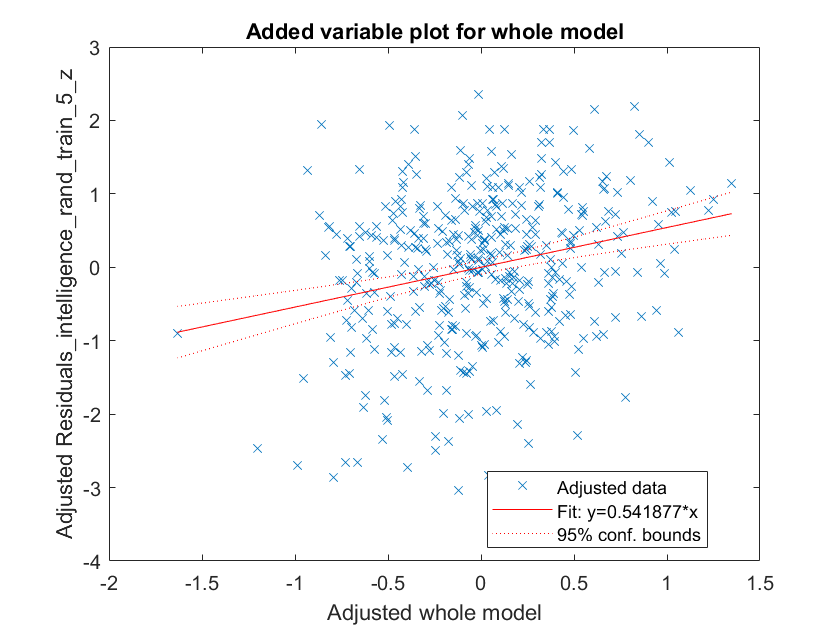

Model_Matrix = [residuals_emotion_pos_train_5_z residuals_emotion_neg_train_5_z residuals_gambling_pos_train_5_z residuals_gambling_neg_train_5_z residuals_language_pos_train_5_z residuals_language_neg_train_5_z residuals_motor_pos_train_5_z residuals_motor_neg_train_5_z residuals_relational_pos_train_5_z residuals_relational_neg_train_5_z residuals_social_pos_train_5_z residuals_social_neg_train_5_z residuals_wm_pos_train_5_z residuals_wm_neg_train_5_z residuals_intelligence_train_5_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_emotion_pos_train_5_z', 'residuals_emotion_neg_train_5_z', 'residuals_gambling_pos_train_5_z', 'residuals_gambling_neg_train_5_z', 'residuals_language_pos_train_5_z', 'residuals_language_neg_train_5_z', 'residuals_motor_pos_train_5_z', 'residuals_motor_neg_train_5_z', 'residuals_relational_pos_train_5_z', 'residuals_relational_neg_train_5_z', 'residuals_social_pos_train_5_z', 'residuals_social_neg_train_5_z', 'residuals_wm_pos_train_5_z', 'residuals_wm_neg_train_5_z','Residuals_intelligence_rand_train_5_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2. Predict the intelligence scores in test samples **

2.1. Test Sample 1 

Get data from lockbox sample 

Age_test_1 = Age_lockbox;
Gender_test_1 = Gender_lockbox;
meanFDJenk_emotion_test_1 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_1 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_1 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_1 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_1 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_1 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_1 = meanFDJenk_wm_lockbox;
LQ_test_1 = LQ_lockbox;

Intelligence_test_1 = Intelligence_lockbox;


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1);
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{1,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{1,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{1,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{1,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{1,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{1,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{1,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{1,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{1,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{1,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{1,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{1,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{1,2};

Take the Mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_emotion_test_1 meanFDJenk_gambling_test_1 meanFDJenk_language_test_1 meanFDJenk_motor_test_1 meanFDJenk_relational_test_1 meanFDJenk_social_test_1 meanFDJenk_wm_test_1 LQ_test_1];



Positive_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_1 = (Positive_all_emotion - Positive_all_pred_emotion_test_1);
residuals_pos_emotion_test_1_z = normalize(residuals_pos_emotion_test_1,"center",c_pos_NMA_emotion_train_1,"scale",s_pos_NMA_emotion_train_1);


Negative_all_pred_emotion_test_1 = predict(mdl_regress_train_1_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_1 = (Negative_all_emotion - Negative_all_pred_emotion_test_1);
residuals_neg_emotion_test_1_z = normalize(residuals_neg_emotion_test_1,"center",c_neg_NMA_emotion_train_1,"scale",s_neg_NMA_emotion_train_1);


Positive_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_1 = (Positive_all_gambling - Positive_all_pred_gambling_test_1);
residuals_pos_gambling_test_1_z = normalize(residuals_pos_gambling_test_1,"center",c_pos_NMA_gambling_train_1,"scale",s_pos_NMA_gambling_train_1);


Negative_all_pred_gambling_test_1 = predict(mdl_regress_train_1_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_1 = (Negative_all_gambling - Negative_all_pred_gambling_test_1);
residuals_neg_gambling_test_1_z = normalize(residuals_neg_gambling_test_1,"center",c_neg_NMA_gambling_train_1,"scale",s_neg_NMA_gambling_train_1);


Positive_all_pred_language_test_1 = predict(mdl_regress_train_1_language_pos_bcs,confounds);

residuals_pos_language_test_1 = (Positive_all_language - Positive_all_pred_language_test_1);
residuals_pos_language_test_1_z = normalize(residuals_pos_language_test_1,"center",c_pos_NMA_language_train_1,"scale",s_pos_NMA_language_train_1);


Negative_all_pred_language_test_1 = predict(mdl_regress_train_1_language_neg_bcs,confounds);

residuals_neg_language_test_1 = (Negative_all_language - Negative_all_pred_language_test_1);
residuals_neg_language_test_1_z = normalize(residuals_neg_language_test_1,"center",c_neg_NMA_language_train_1,"scale",s_neg_NMA_language_train_1);


Positive_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_pos_bcs,confounds);

residuals_pos_motor_test_1 = (Positive_all_motor - Positive_all_pred_motor_test_1);
residuals_pos_motor_test_1_z = normalize(residuals_pos_motor_test_1,"center",c_pos_NMA_motor_train_1,"scale",s_pos_NMA_motor_train_1);


Negative_all_pred_motor_test_1 = predict(mdl_regress_train_1_motor_neg_bcs,confounds);

residuals_neg_motor_test_1 = (Negative_all_motor - Negative_all_pred_motor_test_1);
residuals_neg_motor_test_1_z = normalize(residuals_neg_motor_test_1,"center",c_neg_NMA_motor_train_1,"scale",s_neg_NMA_motor_train_1);



Positive_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_pos_bcs,confounds);

residuals_pos_relational_test_1 = (Positive_all_relational - Positive_all_pred_relational_test_1);
residuals_pos_relational_test_1_z = normalize(residuals_pos_relational_test_1,"center",c_pos_NMA_relational_train_1,"scale",s_pos_NMA_relational_train_1);


Negative_all_pred_relational_test_1 = predict(mdl_regress_train_1_relational_neg_bcs,confounds);

residuals_neg_relational_test_1 = (Negative_all_relational - Negative_all_pred_relational_test_1);
residuals_neg_relational_test_1_z = normalize(residuals_neg_relational_test_1,"center",c_neg_NMA_relational_train_1,"scale",s_neg_NMA_relational_train_1);


Positive_all_pred_social_test_1 = predict(mdl_regress_train_1_social_pos_bcs,confounds);

residuals_pos_social_test_1 = (Positive_all_social - Positive_all_pred_social_test_1);
residuals_pos_social_test_1_z = normalize(residuals_pos_social_test_1,"center",c_pos_NMA_social_train_1,"scale",s_pos_NMA_social_train_1);


Negative_all_pred_social_test_1 = predict(mdl_regress_train_1_social_neg_bcs,confounds);

residuals_neg_social_test_1 = (Negative_all_social - Negative_all_pred_social_test_1);
residuals_neg_social_test_1_z = normalize(residuals_neg_social_test_1,"center",c_neg_NMA_social_train_1,"scale",s_neg_NMA_social_train_1);


Positive_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_pos_bcs,confounds);

residuals_pos_wm_test_1 = (Positive_all_wm - Positive_all_pred_wm_test_1);
residuals_pos_wm_test_1_z = normalize(residuals_pos_wm_test_1,"center",c_pos_NMA_wm_train_1,"scale",s_pos_NMA_wm_train_1);


Negative_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_neg_bcs,confounds);

residuals_neg_wm_test_1 = (Negative_all_wm - Negative_all_pred_wm_test_1);
residuals_neg_wm_test_1_z = normalize(residuals_neg_wm_test_1,"center",c_neg_NMA_wm_train_1,"scale",s_neg_NMA_wm_train_1);

Xnew = [residuals_pos_emotion_test_1_z residuals_neg_emotion_test_1_z residuals_pos_gambling_test_1_z residuals_neg_gambling_test_1_z residuals_pos_language_test_1_z residuals_neg_language_test_1_z residuals_pos_motor_test_1_z residuals_neg_motor_test_1_z residuals_pos_relational_test_1_z residuals_neg_relational_test_1_z residuals_pos_social_test_1_z residuals_neg_social_test_1_z residuals_pos_wm_test_1_z residuals_neg_wm_test_1_z];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r_model_1_rand,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get data from lockbox sample

Age_test_2 = Age_lockbox;
Gender_test_2 = Gender_lockbox;
meanFDJenk_emotion_test_2 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_2 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_2 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_2 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_2 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_2 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_2 = meanFDJenk_wm_lockbox;
LQ_test_2 = LQ_lockbox;

Intelligence_test_2 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{2,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{2,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{2,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{2,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{2,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{2,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{2,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{2,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{2,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{2,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{2,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{2,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{2,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_emotion_test_2 meanFDJenk_gambling_test_2 meanFDJenk_language_test_2 meanFDJenk_motor_test_2 meanFDJenk_relational_test_2 meanFDJenk_social_test_2 meanFDJenk_wm_test_2 LQ_test_2];


Positive_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_2 = (Positive_all_emotion - Positive_all_pred_emotion_test_2);
residuals_pos_emotion_test_2_z = normalize(residuals_pos_emotion_test_2,"center",c_pos_NMA_emotion_train_2,"scale",s_pos_NMA_emotion_train_2);


Negative_all_pred_emotion_test_2 = predict(mdl_regress_train_2_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_2 = (Negative_all_emotion - Negative_all_pred_emotion_test_2);
residuals_neg_emotion_test_2_z = normalize(residuals_neg_emotion_test_2,"center",c_neg_NMA_emotion_train_2,"scale",s_neg_NMA_emotion_train_2);


Positive_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_2 = (Positive_all_gambling - Positive_all_pred_gambling_test_2);
residuals_pos_gambling_test_2_z = normalize(residuals_pos_gambling_test_2,"center",c_pos_NMA_gambling_train_2,"scale",s_pos_NMA_gambling_train_2);


Negative_all_pred_gambling_test_2 = predict(mdl_regress_train_2_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_2 = (Negative_all_gambling - Negative_all_pred_gambling_test_2);
residuals_neg_gambling_test_2_z = normalize(residuals_neg_gambling_test_2,"center",c_neg_NMA_gambling_train_2,"scale",s_neg_NMA_gambling_train_2);



Positive_all_pred_language_test_2 = predict(mdl_regress_train_2_language_pos_bcs,confounds);

residuals_pos_language_test_2 = (Positive_all_language - Positive_all_pred_language_test_2);
residuals_pos_language_test_2_z = normalize(residuals_pos_language_test_2,"center",c_pos_NMA_language_train_2,"scale",s_pos_NMA_language_train_2);


Negative_all_pred_language_test_2 = predict(mdl_regress_train_2_language_neg_bcs,confounds);

residuals_neg_language_test_2 = (Negative_all_language - Negative_all_pred_language_test_2);
residuals_neg_language_test_2_z = normalize(residuals_neg_language_test_2,"center",c_neg_NMA_language_train_2,"scale",s_neg_NMA_language_train_2);


Positive_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_pos_bcs,confounds);

residuals_pos_motor_test_2 = (Positive_all_motor - Positive_all_pred_motor_test_2);
residuals_pos_motor_test_2_z = normalize(residuals_pos_motor_test_2,"center",c_pos_NMA_motor_train_2,"scale",s_pos_NMA_motor_train_2);


Negative_all_pred_motor_test_2 = predict(mdl_regress_train_2_motor_neg_bcs,confounds);

residuals_neg_motor_test_2 = (Negative_all_motor - Negative_all_pred_motor_test_2);
residuals_neg_motor_test_2_z = normalize(residuals_neg_motor_test_2,"center",c_neg_NMA_motor_train_2,"scale",s_neg_NMA_motor_train_2);


Positive_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_pos_bcs,confounds);

residuals_pos_relational_test_2 = (Positive_all_relational - Positive_all_pred_relational_test_2);
residuals_pos_relational_test_2_z = normalize(residuals_pos_relational_test_2,"center",c_pos_NMA_relational_train_2,"scale",s_pos_NMA_relational_train_2);


Negative_all_pred_relational_test_2 = predict(mdl_regress_train_2_relational_neg_bcs,confounds);

residuals_neg_relational_test_2 = (Negative_all_relational - Negative_all_pred_relational_test_2);
residuals_neg_relational_test_2_z = normalize(residuals_neg_relational_test_2,"center",c_neg_NMA_relational_train_2,"scale",s_neg_NMA_relational_train_2);


Positive_all_pred_social_test_2 = predict(mdl_regress_train_2_social_pos_bcs,confounds);

residuals_pos_social_test_2 = (Positive_all_social - Positive_all_pred_social_test_2);
residuals_pos_social_test_2_z = normalize(residuals_pos_social_test_2,"center",c_pos_NMA_social_train_2,"scale",s_pos_NMA_social_train_2);


Negative_all_pred_social_test_2 = predict(mdl_regress_train_2_social_neg_bcs,confounds);

residuals_neg_social_test_2 = (Negative_all_social - Negative_all_pred_social_test_2);
residuals_neg_social_test_2_z = normalize(residuals_neg_social_test_2,"center",c_neg_NMA_social_train_2,"scale",s_neg_NMA_social_train_2);


Positive_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_pos_bcs,confounds);

residuals_pos_wm_test_2 = (Positive_all_wm - Positive_all_pred_wm_test_2);
residuals_pos_wm_test_2_z = normalize(residuals_pos_wm_test_2,"center",c_pos_NMA_wm_train_2,"scale",s_pos_NMA_wm_train_2);


Negative_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_neg_bcs,confounds);

residuals_neg_wm_test_2 = (Negative_all_wm - Negative_all_pred_wm_test_2);
residuals_neg_wm_test_2_z = normalize(residuals_neg_wm_test_2,"center",c_neg_NMA_wm_train_2,"scale",s_neg_NMA_wm_train_2);

Xnew = [residuals_pos_emotion_test_2_z residuals_neg_emotion_test_2_z residuals_pos_gambling_test_2_z residuals_neg_gambling_test_2_z residuals_pos_language_test_2_z residuals_neg_language_test_2_z residuals_pos_motor_test_2_z residuals_neg_motor_test_2_z residuals_pos_relational_test_2_z residuals_neg_relational_test_2_z residuals_pos_social_test_2_z residuals_neg_social_test_2_z residuals_pos_wm_test_2_z residuals_neg_wm_test_2_z];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r_model_2_rand,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get data from lockbox sample 

Age_test_3 = Age_lockbox;
Gender_test_3 = Gender_lockbox;
meanFDJenk_emotion_test_3 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_3 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_3 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_3 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_3 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_3 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_3 = meanFDJenk_wm_lockbox;
LQ_test_3 = LQ_lockbox;

Intelligence_test_3 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{3,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{3,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{3,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{3,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{3,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{3,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{3,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{3,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{3,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{3,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{3,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{3,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{3,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_emotion_test_3 meanFDJenk_gambling_test_3 meanFDJenk_language_test_3 meanFDJenk_motor_test_3 meanFDJenk_relational_test_3 meanFDJenk_social_test_3 meanFDJenk_wm_test_3 LQ_test_3];



Positive_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_3 = (Positive_all_emotion - Positive_all_pred_emotion_test_3);
residuals_pos_emotion_test_3_z = normalize(residuals_pos_emotion_test_3,"center",c_pos_NMA_emotion_train_3,"scale",s_pos_NMA_emotion_train_3);


Negative_all_pred_emotion_test_3 = predict(mdl_regress_train_3_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_3 = (Negative_all_emotion - Negative_all_pred_emotion_test_3);
residuals_neg_emotion_test_3_z = normalize(residuals_neg_emotion_test_3,"center",c_neg_NMA_emotion_train_3,"scale",s_neg_NMA_emotion_train_3);



Positive_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_3 = (Positive_all_gambling - Positive_all_pred_gambling_test_3);
residuals_pos_gambling_test_3_z = normalize(residuals_pos_gambling_test_3,"center",c_pos_NMA_gambling_train_3,"scale",s_pos_NMA_gambling_train_3);



Negative_all_pred_gambling_test_3 = predict(mdl_regress_train_3_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_3 = (Negative_all_gambling - Negative_all_pred_gambling_test_3);
residuals_neg_gambling_test_3_z = normalize(residuals_neg_gambling_test_3,"center",c_neg_NMA_gambling_train_3,"scale",s_neg_NMA_gambling_train_3);


Positive_all_pred_language_test_3 = predict(mdl_regress_train_3_language_pos_bcs,confounds);

residuals_pos_language_test_3 = (Positive_all_language - Positive_all_pred_language_test_3);
residuals_pos_language_test_3_z = normalize(residuals_pos_language_test_3,"center",c_pos_NMA_language_train_3,"scale",s_pos_NMA_language_train_3);


Negative_all_pred_language_test_3 = predict(mdl_regress_train_3_language_neg_bcs,confounds);

residuals_neg_language_test_3 = (Negative_all_language - Negative_all_pred_language_test_3);
residuals_neg_language_test_3_z = normalize(residuals_neg_language_test_3,"center",c_neg_NMA_language_train_3,"scale",s_neg_NMA_language_train_3);


Positive_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_pos_bcs,confounds);

residuals_pos_motor_test_3 = (Positive_all_motor - Positive_all_pred_motor_test_3);
residuals_pos_motor_test_3_z = normalize(residuals_pos_motor_test_3,"center",c_pos_NMA_motor_train_3,"scale",s_pos_NMA_motor_train_3);


Negative_all_pred_motor_test_3 = predict(mdl_regress_train_3_motor_neg_bcs,confounds);

residuals_neg_motor_test_3 = (Negative_all_motor - Negative_all_pred_motor_test_3);
residuals_neg_motor_test_3_z = normalize(residuals_neg_motor_test_3,"center",c_neg_NMA_motor_train_3,"scale",s_neg_NMA_motor_train_3);

Positive_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_pos_bcs,confounds);

residuals_pos_relational_test_3 = (Positive_all_relational - Positive_all_pred_relational_test_3);
residuals_pos_relational_test_3_z = normalize(residuals_pos_relational_test_3,"center",c_pos_NMA_relational_train_3,"scale",s_pos_NMA_relational_train_3);


Negative_all_pred_relational_test_3 = predict(mdl_regress_train_3_relational_neg_bcs,confounds);

residuals_neg_relational_test_3 = (Negative_all_relational - Negative_all_pred_relational_test_3);
residuals_neg_relational_test_3_z = normalize(residuals_neg_relational_test_3,"center",c_neg_NMA_relational_train_3,"scale",s_neg_NMA_relational_train_3);


Positive_all_pred_social_test_3 = predict(mdl_regress_train_3_social_pos_bcs,confounds);

residuals_pos_social_test_3 = (Positive_all_social - Positive_all_pred_social_test_3);
residuals_pos_social_test_3_z = normalize(residuals_pos_social_test_3,"center",c_pos_NMA_social_train_3,"scale",s_pos_NMA_social_train_3);


Negative_all_pred_social_test_3 = predict(mdl_regress_train_3_social_neg_bcs,confounds);

residuals_neg_social_test_3 = (Negative_all_social - Negative_all_pred_social_test_3);
residuals_neg_social_test_3_z = normalize(residuals_neg_social_test_3,"center",c_neg_NMA_social_train_3,"scale",s_neg_NMA_social_train_3);



Positive_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_pos_bcs,confounds);

residuals_pos_wm_test_3 = (Positive_all_wm - Positive_all_pred_wm_test_3);
residuals_pos_wm_test_3_z = normalize(residuals_pos_wm_test_3,"center",c_pos_NMA_wm_train_3,"scale",s_pos_NMA_wm_train_3);


Negative_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_neg_bcs,confounds);

residuals_neg_wm_test_3 = (Negative_all_wm - Negative_all_pred_wm_test_3);
residuals_neg_wm_test_3_z = normalize(residuals_neg_wm_test_3,"center",c_neg_NMA_wm_train_3,"scale",s_neg_NMA_wm_train_3);

Xnew = [residuals_pos_emotion_test_3_z residuals_neg_emotion_test_3_z residuals_pos_gambling_test_3_z residuals_neg_gambling_test_3_z residuals_pos_language_test_3_z residuals_neg_language_test_3_z residuals_pos_motor_test_3_z residuals_neg_motor_test_3_z residuals_pos_relational_test_3_z residuals_neg_relational_test_3_z residuals_pos_social_test_3_z residuals_neg_social_test_3_z residuals_pos_wm_test_3_z residuals_neg_wm_test_3_z];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);

[r_model_3_rand,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get data from lockbos sample 

Age_test_4 = Age_lockbox;
Gender_test_4 = Gender_lockbox;
meanFDJenk_emotion_test_4 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_4 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_4 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_4 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_4 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_4 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_4 = meanFDJenk_wm_lockbox;
LQ_test_4 = LQ_lockbox;

Intelligence_test_4 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];
Intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - Intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{4,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{4,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{4,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{4,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{4,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{4,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{4,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{4,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{4,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{4,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{4,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{4,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{4,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables and normalize the residuals 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_emotion_test_4 meanFDJenk_gambling_test_4 meanFDJenk_language_test_4 meanFDJenk_motor_test_4 meanFDJenk_relational_test_4 meanFDJenk_social_test_4 meanFDJenk_wm_test_4 LQ_test_4];


Positive_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_4 = (Positive_all_emotion - Positive_all_pred_emotion_test_4);
residuals_pos_emotion_test_4_z = normalize(residuals_pos_emotion_test_4,"center",c_pos_NMA_emotion_train_4,"scale",s_pos_NMA_emotion_train_4);


Negative_all_pred_emotion_test_4 = predict(mdl_regress_train_4_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_4 = (Negative_all_emotion - Negative_all_pred_emotion_test_4);
residuals_neg_emotion_test_4_z = normalize(residuals_neg_emotion_test_4,"center",c_neg_NMA_emotion_train_4,"scale",s_neg_NMA_emotion_train_4);


Positive_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_4 = (Positive_all_gambling - Positive_all_pred_gambling_test_4);
residuals_pos_gambling_test_4_z = normalize(residuals_pos_gambling_test_4,"center",c_pos_NMA_gambling_train_4,"scale",s_pos_NMA_gambling_train_4);



Negative_all_pred_gambling_test_4 = predict(mdl_regress_train_4_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_4 = (Negative_all_gambling - Negative_all_pred_gambling_test_4);
residuals_neg_gambling_test_4_z = normalize(residuals_neg_gambling_test_4,"center",c_neg_NMA_gambling_train_4,"scale",s_neg_NMA_gambling_train_4);


Positive_all_pred_language_test_4 = predict(mdl_regress_train_4_language_pos_bcs,confounds);

residuals_pos_language_test_4 = (Positive_all_language - Positive_all_pred_language_test_4);
residuals_pos_language_test_4_z = normalize(residuals_pos_language_test_4,"center",c_pos_NMA_language_train_4,"scale",s_pos_NMA_language_train_4);


Negative_all_pred_language_test_4 = predict(mdl_regress_train_4_language_neg_bcs,confounds);

residuals_neg_language_test_4 = (Negative_all_language - Negative_all_pred_language_test_4);
residuals_neg_language_test_4_z = normalize(residuals_neg_language_test_4,"center",c_neg_NMA_language_train_4,"scale",s_neg_NMA_language_train_4);


Positive_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_pos_bcs,confounds);

residuals_pos_motor_test_4 = (Positive_all_motor - Positive_all_pred_motor_test_4);
residuals_pos_motor_test_4_z = normalize(residuals_pos_motor_test_4,"center",c_pos_NMA_motor_train_4,"scale",s_pos_NMA_motor_train_4);



Negative_all_pred_motor_test_4 = predict(mdl_regress_train_4_motor_neg_bcs,confounds);

residuals_neg_motor_test_4 = (Negative_all_motor - Negative_all_pred_motor_test_4);
residuals_neg_motor_test_4_z = normalize(residuals_neg_motor_test_4,"center",c_neg_NMA_motor_train_4,"scale",s_neg_NMA_motor_train_4);


Positive_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_pos_bcs,confounds);

residuals_pos_relational_test_4 = (Positive_all_relational - Positive_all_pred_relational_test_4);
residuals_pos_relational_test_4_z = normalize(residuals_pos_relational_test_4,"center",c_pos_NMA_relational_train_4,"scale",s_pos_NMA_relational_train_4);


Negative_all_pred_relational_test_4 = predict(mdl_regress_train_4_relational_neg_bcs,confounds);

residuals_neg_relational_test_4 = (Negative_all_relational - Negative_all_pred_relational_test_4);
residuals_neg_relational_test_4_z = normalize(residuals_neg_relational_test_4,"center",c_neg_NMA_relational_train_4,"scale",s_neg_NMA_relational_train_4);


Positive_all_pred_social_test_4 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_4 = (Positive_all_social - Positive_all_pred_social_test_4);
residuals_pos_social_test_4_z = normalize(residuals_pos_social_test_4,"center",c_pos_NMA_social_train_4,"scale",s_pos_NMA_social_train_4);


Negative_all_pred_social_test_4 = predict(mdl_regress_train_4_social_neg_bcs,confounds);

residuals_neg_social_test_4 = (Negative_all_social - Negative_all_pred_social_test_4);
residuals_neg_social_test_4_z = normalize(residuals_neg_social_test_4,"center",c_neg_NMA_social_train_4,"scale",s_neg_NMA_social_train_4);


Positive_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_pos_bcs,confounds);

residuals_pos_wm_test_4 = (Positive_all_wm - Positive_all_pred_wm_test_4);
residuals_pos_wm_test_4_z = normalize(residuals_pos_wm_test_4,"center",c_pos_NMA_wm_train_4,"scale",s_pos_NMA_wm_train_4);


Negative_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_neg_bcs,confounds);

residuals_neg_wm_test_4 = (Negative_all_wm - Negative_all_pred_wm_test_4);
residuals_neg_wm_test_4_z = normalize(residuals_neg_wm_test_4,"center",c_neg_NMA_wm_train_4,"scale",s_neg_NMA_wm_train_4);

Xnew = [residuals_pos_emotion_test_4_z residuals_neg_emotion_test_4_z residuals_pos_gambling_test_4_z residuals_neg_gambling_test_4_z residuals_pos_language_test_4_z residuals_neg_language_test_4_z residuals_pos_motor_test_4_z residuals_neg_motor_test_4_z residuals_pos_relational_test_4_z residuals_neg_relational_test_4_z residuals_pos_social_test_4_z residuals_neg_social_test_4_z residuals_pos_wm_test_4_z residuals_neg_wm_test_4_z];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);

[r_model_4_rand,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get data from lockbox sample

Age_test_5 = Age_lockbox;
Gender_test_5 = Gender_lockbox;
meanFDJenk_emotion_test_5 = meanFDJenk_emotion_lockbox;
meanFDJenk_gambling_test_5 = meanFDJenk_gambling_lockbox;
meanFDJenk_language_test_5 = meanFDJenk_language_lockbox;
meanFDJenk_motor_test_5 = meanFDJenk_motor_lockbox;
meanFDJenk_relational_test_5 = meanFDJenk_relational_lockbox;
meanFDJenk_social_test_5 = meanFDJenk_social_lockbox;
meanFDJenk_wm_test_5 = meanFDJenk_wm_lockbox;
LQ_test_5 = LQ_lockbox;

Intelligence_test_5 = Intelligence_lockbox;

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5);
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMAs

Best_case_scenario_r_values_pos_emotion = Best_case_scenario_test_samples_emotion{5,1};
Best_case_scenario_r_values_neg_emotion = Best_case_scenario_test_samples_emotion{5,2};

Best_case_scenario_r_values_pos_gambling = Best_case_scenario_test_samples_gambling{5,1};
Best_case_scenario_r_values_neg_gambing = Best_case_scenario_test_samples_gambling{5,2};

Best_case_scenario_r_values_pos_language = Best_case_scenario_test_samples_language{5,1};
Best_case_scenario_r_values_neg_language = Best_case_scenario_test_samples_language{5,2};

Best_case_scenario_r_values_pos_motor = Best_case_scenario_test_samples_motor{5,1};
Best_case_scenario_r_values_neg_motor = Best_case_scenario_test_samples_motor{5,2};

Best_case_scenario_r_values_pos_relational = Best_case_scenario_test_samples_relational{5,1};
Best_case_scenario_r_values_neg_relational = Best_case_scenario_test_samples_relational{5,2};

Best_case_scenario_r_values_pos_social = Best_case_scenario_test_samples_social{5,1};
Best_case_scenario_r_values_neg_social = Best_case_scenario_test_samples_social{5,2};

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{5,2};

Take the mean per subject

Positive_all_emotion = nanmean(Best_case_scenario_r_values_pos_emotion,2);
Negative_all_emotion = nanmean(Best_case_scenario_r_values_neg_emotion,2);

Positive_all_gambling = nanmean(Best_case_scenario_r_values_pos_gambling,2);
Negative_all_gambling = nanmean(Best_case_scenario_r_values_neg_gambing,2);

Positive_all_language = nanmean(Best_case_scenario_r_values_pos_language,2);
Negative_all_language = nanmean(Best_case_scenario_r_values_neg_language,2);

Positive_all_motor = nanmean(Best_case_scenario_r_values_pos_motor,2);
Negative_all_motor = nanmean(Best_case_scenario_r_values_neg_motor,2);

Positive_all_relational = nanmean(Best_case_scenario_r_values_pos_relational,2);
Negative_all_relational = nanmean(Best_case_scenario_r_values_neg_relational,2);

Positive_all_social = nanmean(Best_case_scenario_r_values_pos_social,2);
Negative_all_social = nanmean(Best_case_scenario_r_values_neg_social,2);

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_emotion_test_5 meanFDJenk_gambling_test_5 meanFDJenk_language_test_5 meanFDJenk_motor_test_5 meanFDJenk_relational_test_5 meanFDJenk_social_test_5 meanFDJenk_wm_test_5 LQ_test_5];



Positive_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_pos_bcs,confounds);

residuals_pos_emotion_test_5 = (Positive_all_emotion - Positive_all_pred_emotion_test_5);
residuals_pos_emotion_test_5_z = normalize(residuals_pos_emotion_test_5,"center",c_pos_NMA_emotion_train_5,"scale",s_pos_NMA_emotion_train_5);


Negative_all_pred_emotion_test_5 = predict(mdl_regress_train_5_emotion_neg_bcs,confounds);

residuals_neg_emotion_test_5 = (Negative_all_emotion - Negative_all_pred_emotion_test_5);
residuals_neg_emotion_test_5_z = normalize(residuals_neg_emotion_test_5,"center",c_neg_NMA_emotion_train_5,"scale",s_neg_NMA_emotion_train_5);


Positive_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_pos_bcs,confounds);

residuals_pos_gambling_test_5 = (Positive_all_gambling - Positive_all_pred_gambling_test_5);
residuals_pos_gambling_test_5_z = normalize(residuals_pos_gambling_test_5,"center",c_pos_NMA_gambling_train_5,"scale",s_pos_NMA_gambling_train_5);


Negative_all_pred_gambling_test_5 = predict(mdl_regress_train_5_gambling_neg_bcs,confounds);

residuals_neg_gambling_test_5 = (Negative_all_gambling - Negative_all_pred_gambling_test_5);
residuals_neg_gambling_test_5_z = normalize(residuals_neg_gambling_test_5,"center",c_neg_NMA_gambling_train_5,"scale",s_neg_NMA_gambling_train_5);


Positive_all_pred_language_test_5 = predict(mdl_regress_train_5_language_pos_bcs,confounds);

residuals_pos_language_test_5 = (Positive_all_language - Positive_all_pred_language_test_5);
residuals_pos_language_test_5_z = normalize(residuals_pos_language_test_5,"center",c_pos_NMA_language_train_5,"scale",s_pos_NMA_language_train_5);


Negative_all_pred_language_test_5 = predict(mdl_regress_train_5_language_neg_bcs,confounds);

residuals_neg_language_test_5 = (Negative_all_language - Negative_all_pred_language_test_5);
residuals_neg_language_test_5_z = normalize(residuals_neg_language_test_5,"center",c_neg_NMA_language_train_5,"scale",s_neg_NMA_language_train_5);


Positive_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_pos_bcs,confounds);

residuals_pos_motor_test_5 = (Positive_all_motor - Positive_all_pred_motor_test_5);
residuals_pos_motor_test_5_z = normalize(residuals_pos_motor_test_5,"center",c_pos_NMA_motor_train_5,"scale",s_pos_NMA_motor_train_5);


Negative_all_pred_motor_test_5 = predict(mdl_regress_train_5_motor_neg_bcs,confounds);

residuals_neg_motor_test_5 = (Negative_all_motor - Negative_all_pred_motor_test_5);
residuals_neg_motor_test_5_z = normalize(residuals_neg_motor_test_5,"center",c_neg_NMA_motor_train_5,"scale",s_neg_NMA_motor_train_5);


Positive_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_pos_bcs,confounds);

residuals_pos_relational_test_5 = (Positive_all_relational - Positive_all_pred_relational_test_5);
residuals_pos_relational_test_5_z = normalize(residuals_pos_relational_test_5,"center",c_pos_NMA_relational_train_5,"scale",s_pos_NMA_relational_train_5);


Negative_all_pred_relational_test_5 = predict(mdl_regress_train_5_relational_neg_bcs,confounds);

residuals_neg_relational_test_5 = (Negative_all_relational - Negative_all_pred_relational_test_5);
residuals_neg_relational_test_5_z = normalize(residuals_neg_relational_test_5,"center",c_neg_NMA_relational_train_5,"scale",s_neg_NMA_relational_train_5);


Positive_all_pred_social_test_5 = predict(mdl_regress_train_4_social_pos_bcs,confounds);

residuals_pos_social_test_5 = (Positive_all_social - Positive_all_pred_social_test_5);
residuals_pos_social_test_5_z = normalize(residuals_pos_social_test_5,"center",c_pos_NMA_social_train_5,"scale",s_pos_NMA_social_train_5);


Negative_all_pred_social_test_5 = predict(mdl_regress_train_5_social_neg_bcs,confounds);

residuals_neg_social_test_5 = (Negative_all_social - Negative_all_pred_social_test_5);
residuals_neg_social_test_5_z = normalize(residuals_neg_social_test_5,"center",c_neg_NMA_social_train_5,"scale",s_neg_NMA_social_train_5);


Positive_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_pos_bcs,confounds);

residuals_pos_wm_test_5 = (Positive_all_wm - Positive_all_pred_wm_test_5);
residuals_pos_wm_test_5_z = normalize(residuals_pos_wm_test_5,"center",c_pos_NMA_wm_train_5,"scale",s_pos_NMA_wm_train_5);


Negative_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_neg_bcs,confounds);

residuals_neg_wm_test_5 = (Negative_all_wm - Negative_all_pred_wm_test_5);
residuals_neg_wm_test_5_z = normalize(residuals_neg_wm_test_5,"center",c_neg_NMA_wm_train_5,"scale",s_neg_NMA_wm_train_5);

Xnew = [residuals_pos_emotion_test_5_z residuals_neg_emotion_test_5_z residuals_pos_gambling_test_5_z residuals_neg_gambling_test_5_z residuals_pos_language_test_5_z residuals_neg_language_test_5_z residuals_pos_motor_test_5_z residuals_neg_motor_test_5_z residuals_pos_relational_test_5_z residuals_neg_relational_test_5_z residuals_pos_social_test_5_z residuals_neg_social_test_5_z residuals_pos_wm_test_5_z residuals_neg_wm_test_5_z];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r_model_5_rand,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3. Take the average of the performance from the 5 models **

correlations_5_rand_models = [r_model_1_rand r_model_2_rand r_model_3_rand r_model_4_rand r_model_5_rand];

z_scores_correlation_5_random_models = atanh(correlations_5_rand_models);

average_z_scores_correlation_5_random_models = mean(z_scores_correlation_5_random_models);

average_correlation_5_random_models_final = tanh(average_z_scores_correlation_5_random_models);

**4. Save rho_final & pval_final for permutation test **

Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = average_correlation_5_random_models_final;

**End permutation test**

end

end

**4. Analysis Section **

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_HCP(:,1))

all_rhos_final_correlations = 100×1
    0.2035
    0.1951
    0.1878
    0.1959
    0.1940
    0.2065
    0.2096
    0.2048
    0.1996
    0.2011



all_rhos_final_correlations_z_scores = atanh(all_rhos_final_correlations);

mean_all_rhos_final_correlations_z_score = mean(all_rhos_final_correlations_z_scores);

mean_all_rhos_final_correlations_final = tanh(mean_all_rhos_final_correlations_z_score)

mean_all_rhos_final_correlations_final = 0.1992


Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho);

find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations_final) 


ans =

  0×1 empty double column vector



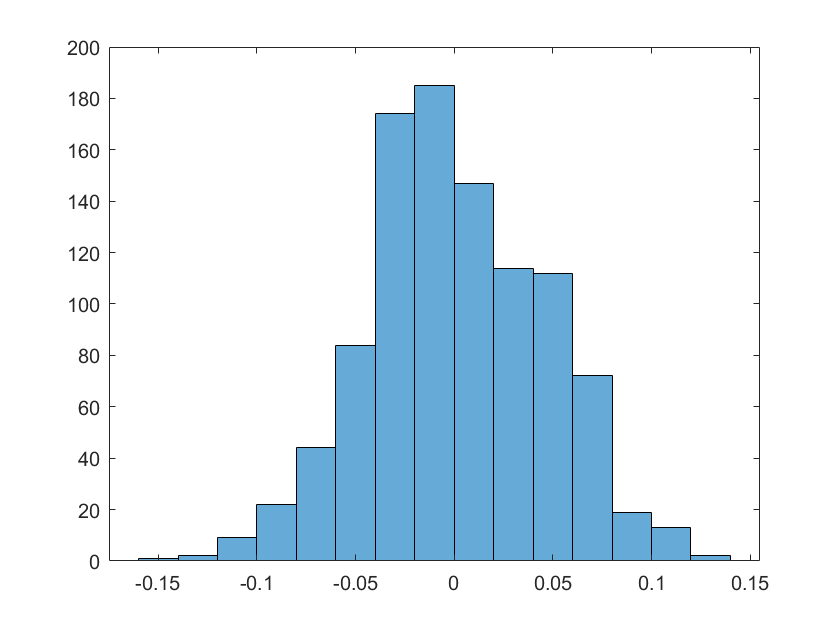

histogram(Permutation_test_all_cross_val_rounds_rho_mat)